## Definizione fisica del sistema (overlook)

L'obiettivo di questo progetto è quello di stabilizzare una mensola incernierata nella posizione verticale alta. Per tutta la trattazione assumeremo che la mensola sia accomunabile al pendolo, poichè la dinamica descritta è la stessa.

Il sistema è descitto dalle equazioni: $\left\{ 
    \begin{array}{l}
        \dot x_1 = x_2
        \\\dot x_2= -\frac {g}{l} sin(x_1) - \frac {b}{ml^2} x_2 + \frac{u(t)}{ml^2} 
        \\ y=x_1
    \end{array} 
\right.
$ in cui:

$x_1


$ rappresenta l'angolo in radianti del pendolo, rispetto alla verticale

$x_2
$ rappresenta la velocità angolare del pendolo

$g$ è l'accelerazione di gravità

$l$ è la lunghezza del pendolo

$b$ è un coefficiente di attrito viscoso

$m$ è la massa del pendolo

$u(t)
$ è l'ingresso di controllo, la coppia applicata

$y 
$ è l'uscita del sistema, ovvero $x_1$

La prima equazione lega i due stati del sistema, la derivata della posizione angolare è la velocità angolare, mentre la seconda rappresenta l'accelerazione angolare del pendolo legata, in generale, alla combinazione dei termini sopra descritti. Il comportamento del sistema dipenderà da diversi fattori, tra cui la lunghezza del pendolo, la massa, il coefficiente di attrito e l'ingresso di controllo. La non linearità del sistema è dovuta dalla dipendenza del $si
n(x_1)$. Questo tipo di sistema è comunemente studiato in teoria del controllo e richiede spesso l'uso di tecniche di controllo avanzate, come quelle viste durante il corso di Advanced Control, per stabilizzare il pendolo o per consentire l'inseguimento di una traiettoria desiderata.

Nel nostro caso i parametri sopra descritti corrispondono a: 


$$g = 9.81$$
 


$$l=1$$



$$b=0.1$$



$$m=1$$


## Analisi della risposta del sistema a ciclo aperto da diverse condizioni iniziali

Per analizzare il sistema fino in fondo, si è deciso di simularlo a ciclo aperto da diverse condizioni iniziali, per effettuare questi esperimenti, è stato descritto il sistema in termini di funzione matlab, nel file **function_WP1.m,** a sua volta riutilizzato per permettere agli script simulink di simulare correttamente il sistema non lineare. Lo schema simulink sfruttato è:

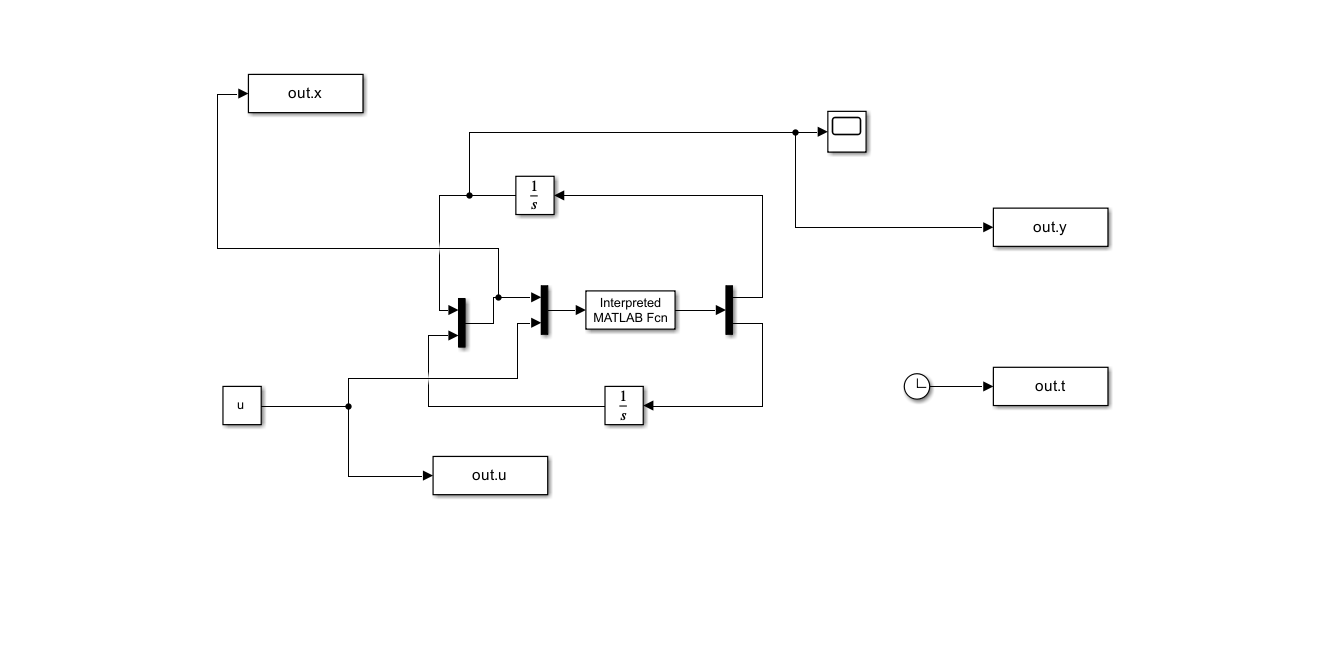

imshow(imread("img/WP1openloopscheme.png"))

Una prima simulazione è stata effettuata a partire dalle seguenti condizioni iniziali:

clear all;
close all;

x1 = 0;
x2 = 0;
u=0;

simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

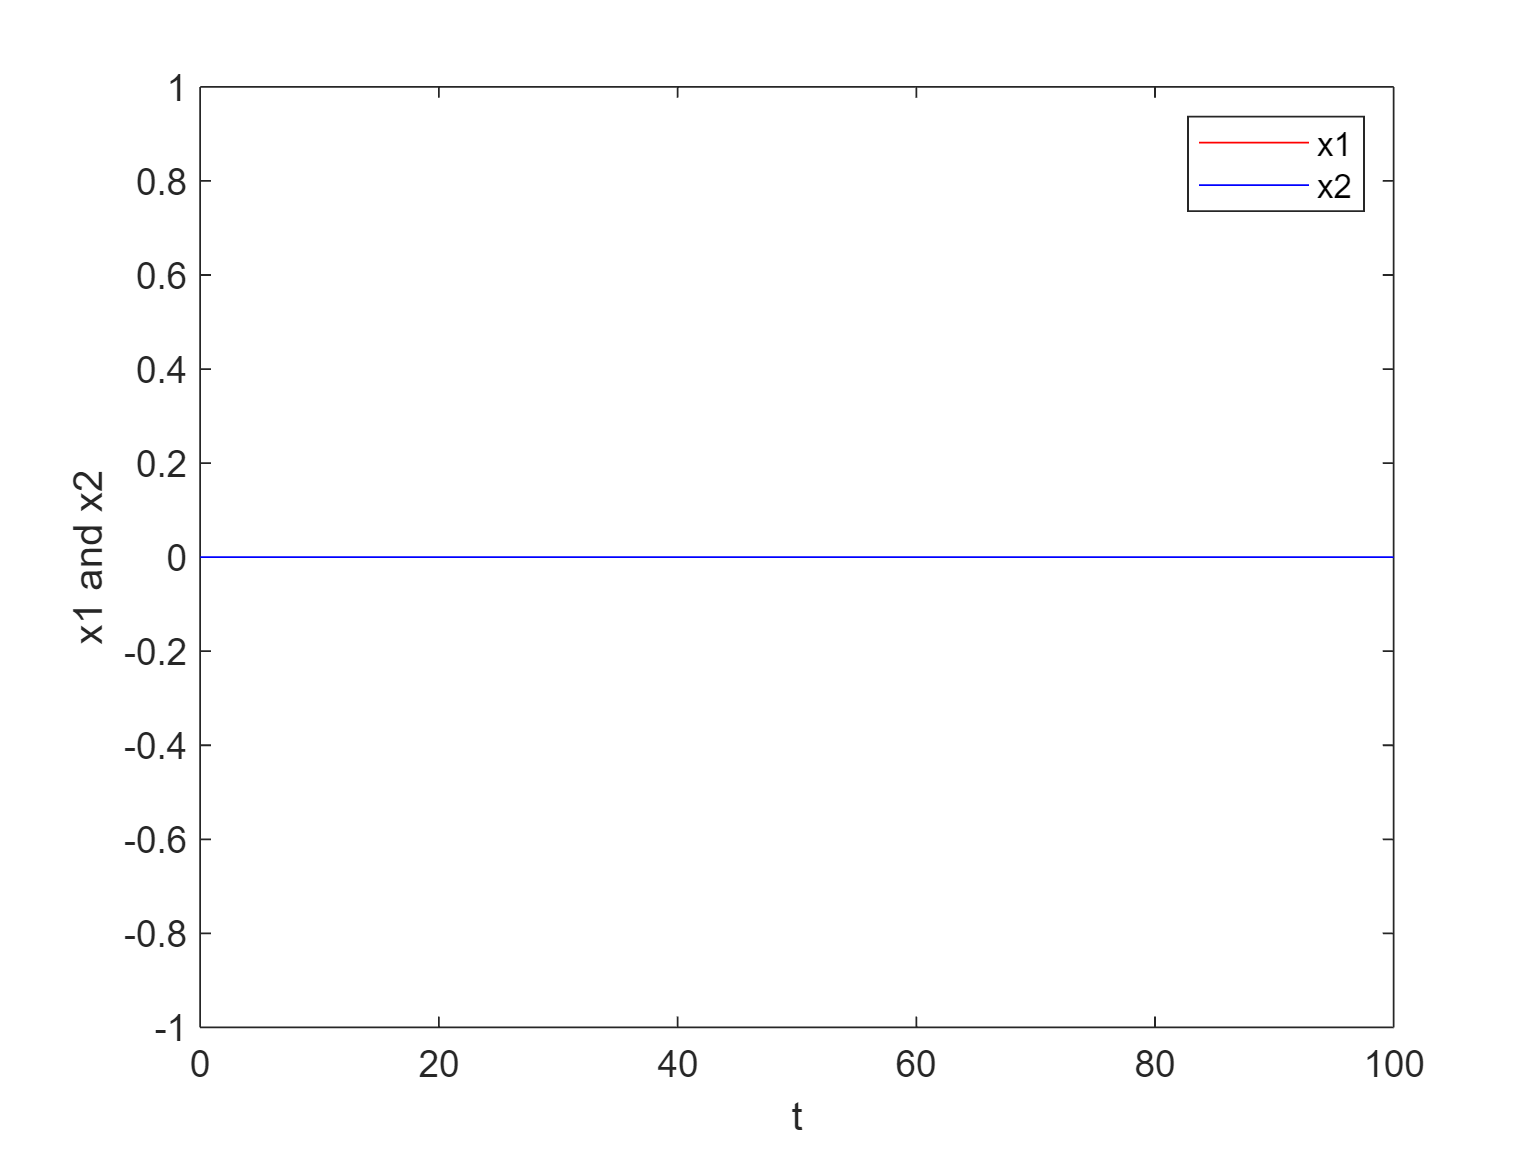

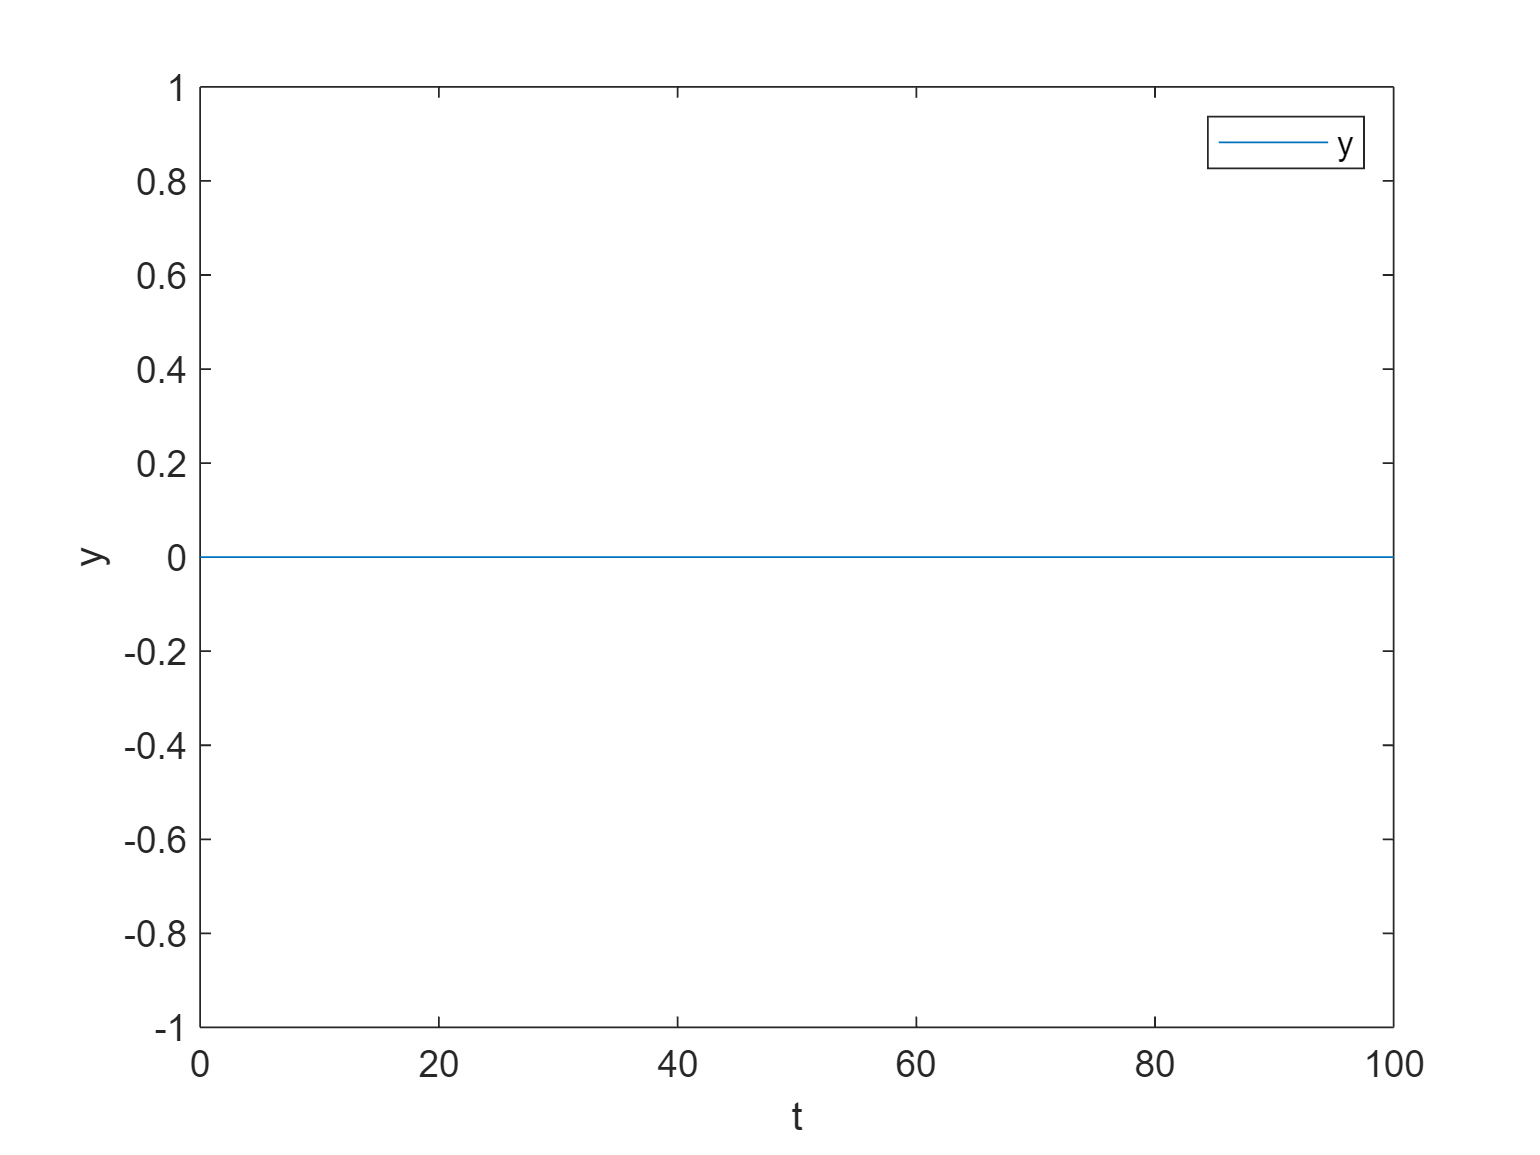

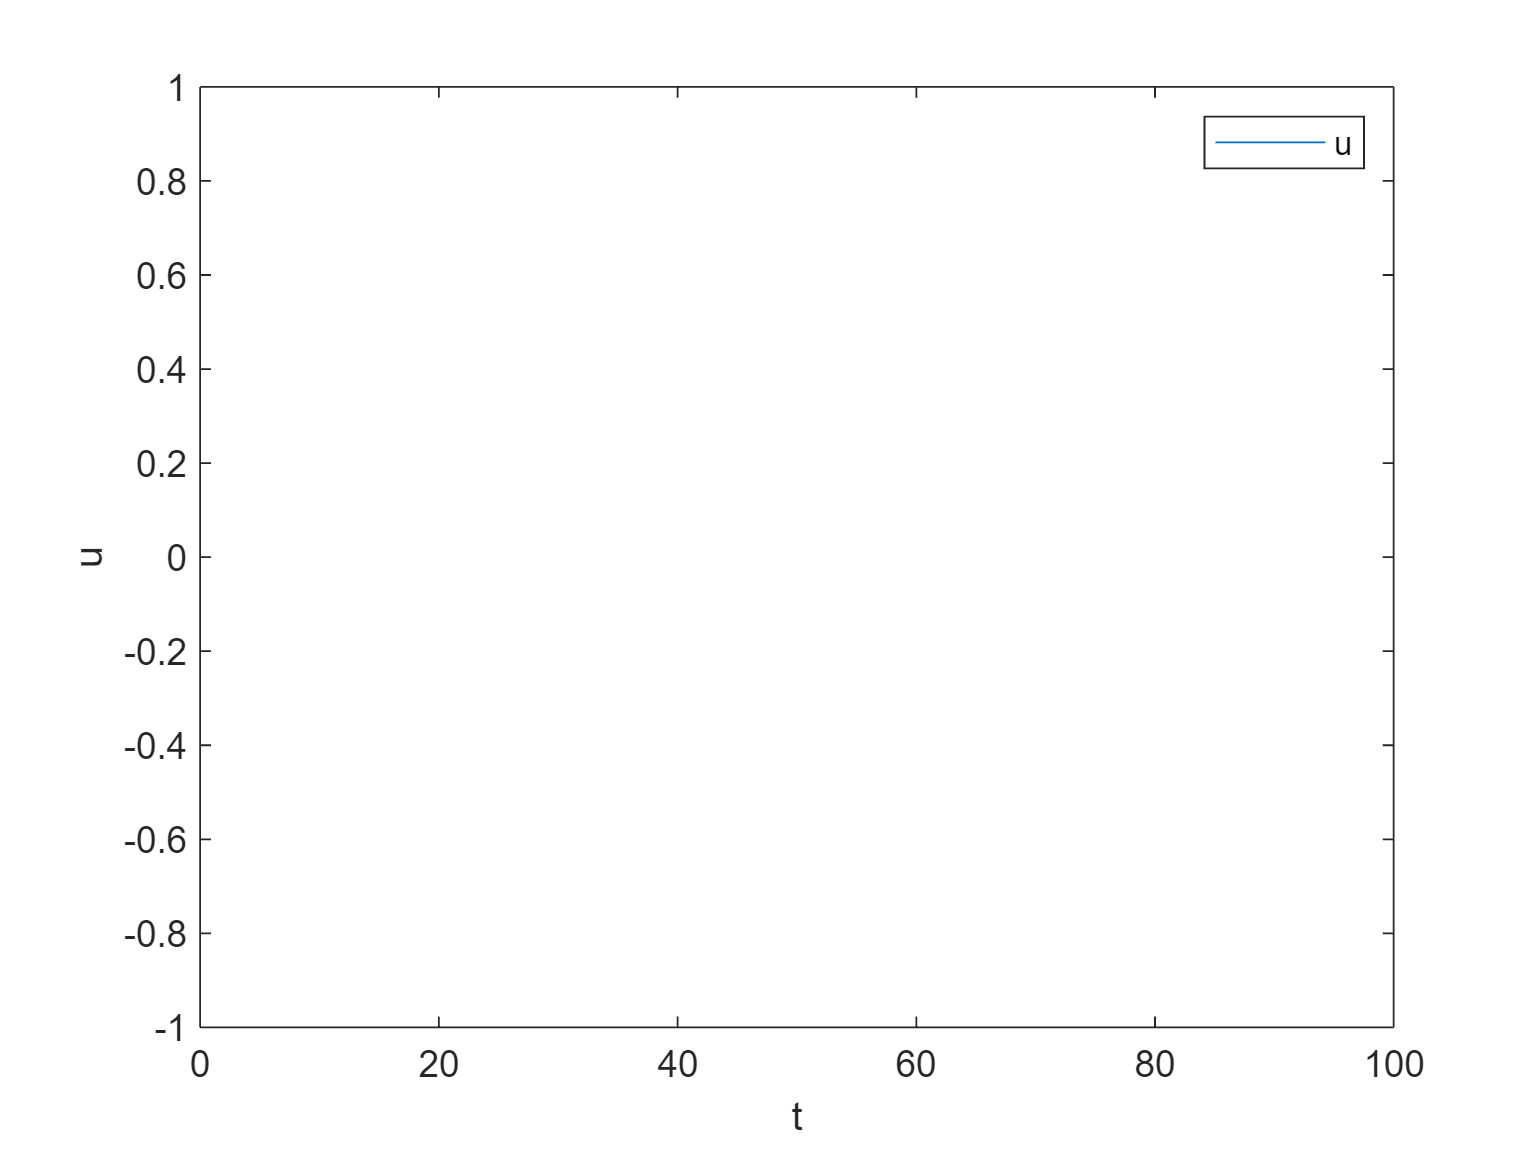

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Nella prima situazione, il punto di partenza è il punto di equilibrio stabile per $u=0$, di conseguenza il sistema rimane nel punto di equilibrio $[0, 0]
$ senza oscillazioni

Proseguiamo con l'analisi del sistema da un'altra condizione iniziale:

x1=pi/2;
x2=0;
u=0;
simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

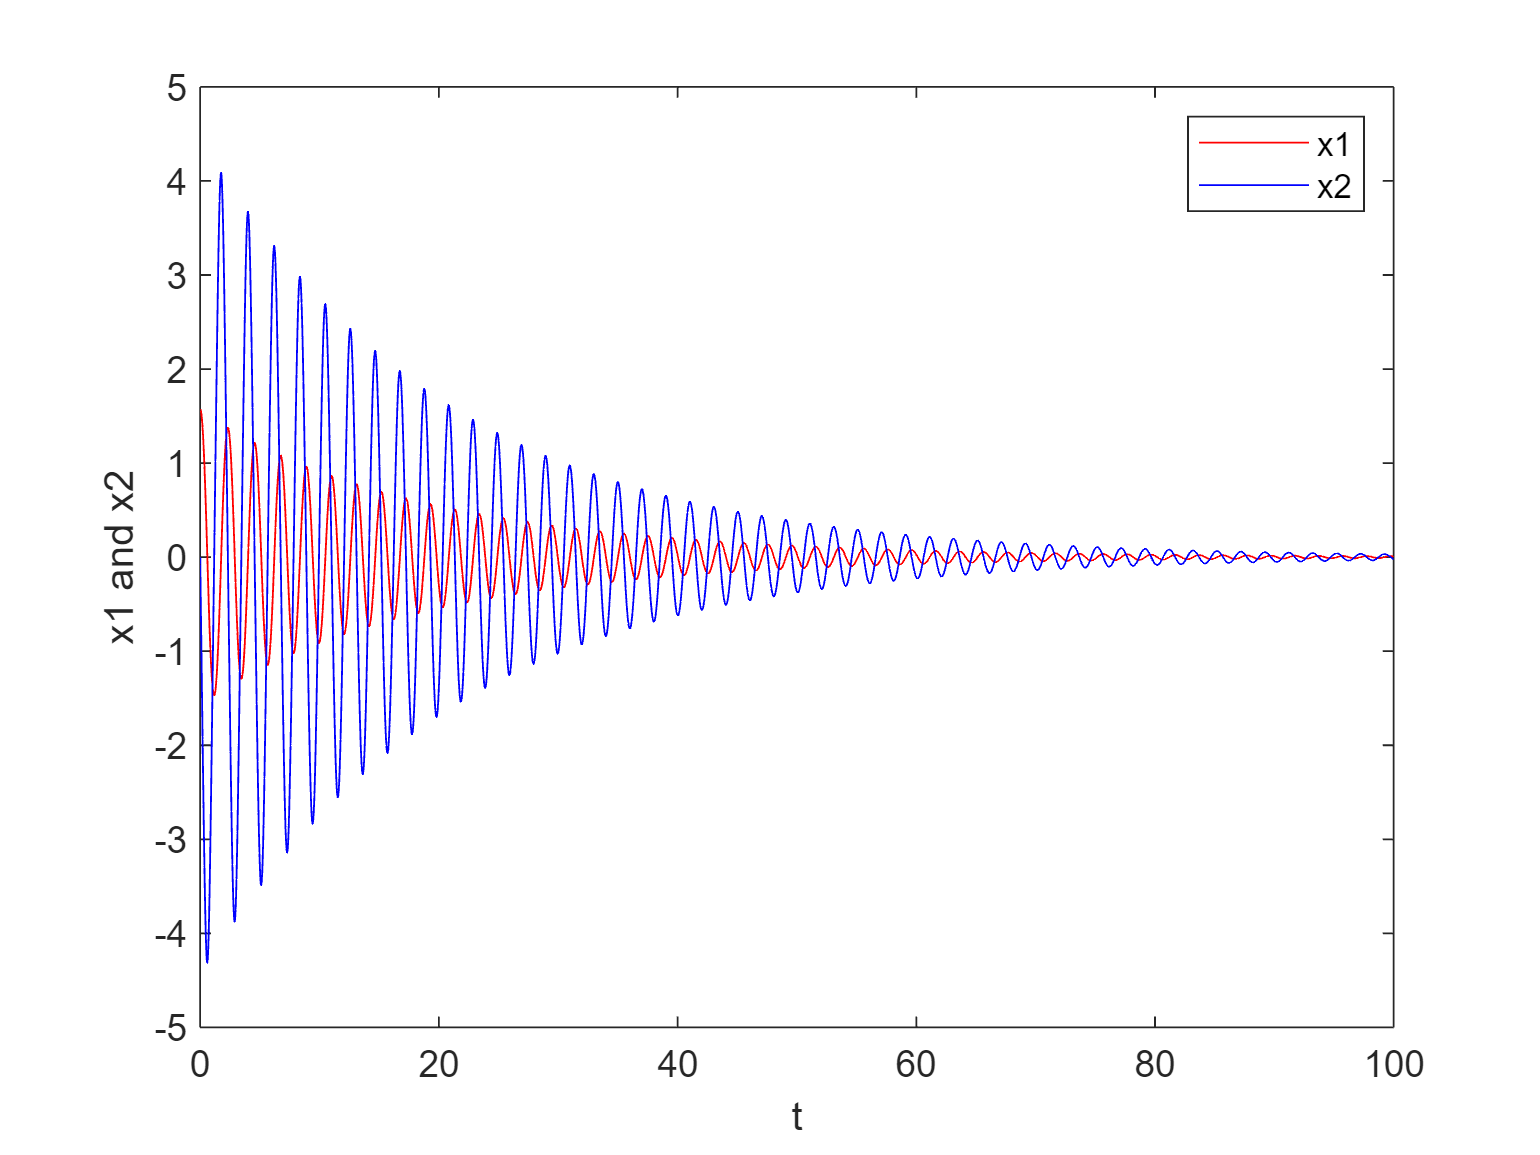

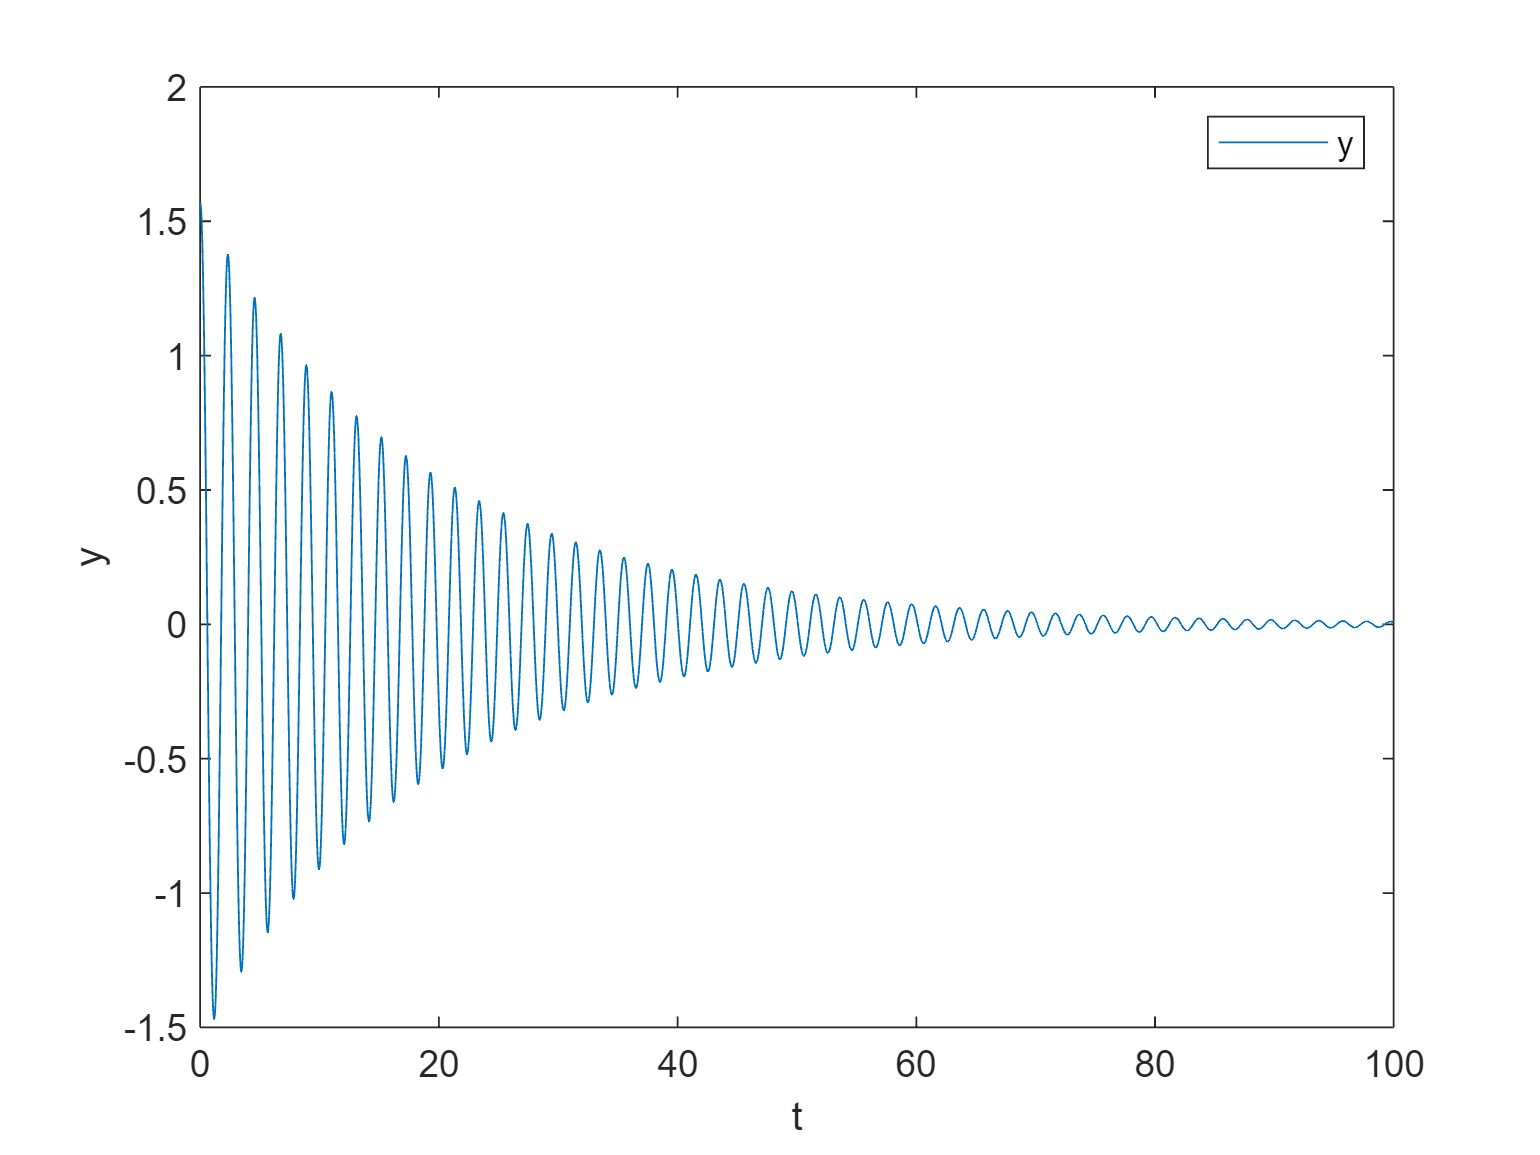

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Nel secondo caso, partiamo da una situazione iniziale diversa per la posizione del pendolo, in questo caso $ \frac{\pi}{2},$ dato che il punto $[0, 0]
$ è un fuoco attrattivo, il sistema tenderà a raggiungere il punto di equilibrio, oscillando fino a convergenza

Proseguiamo con l'analisi del sistema da un'altra condizione iniziale:

x1=pi/2;
x2=2;
u=0;
simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

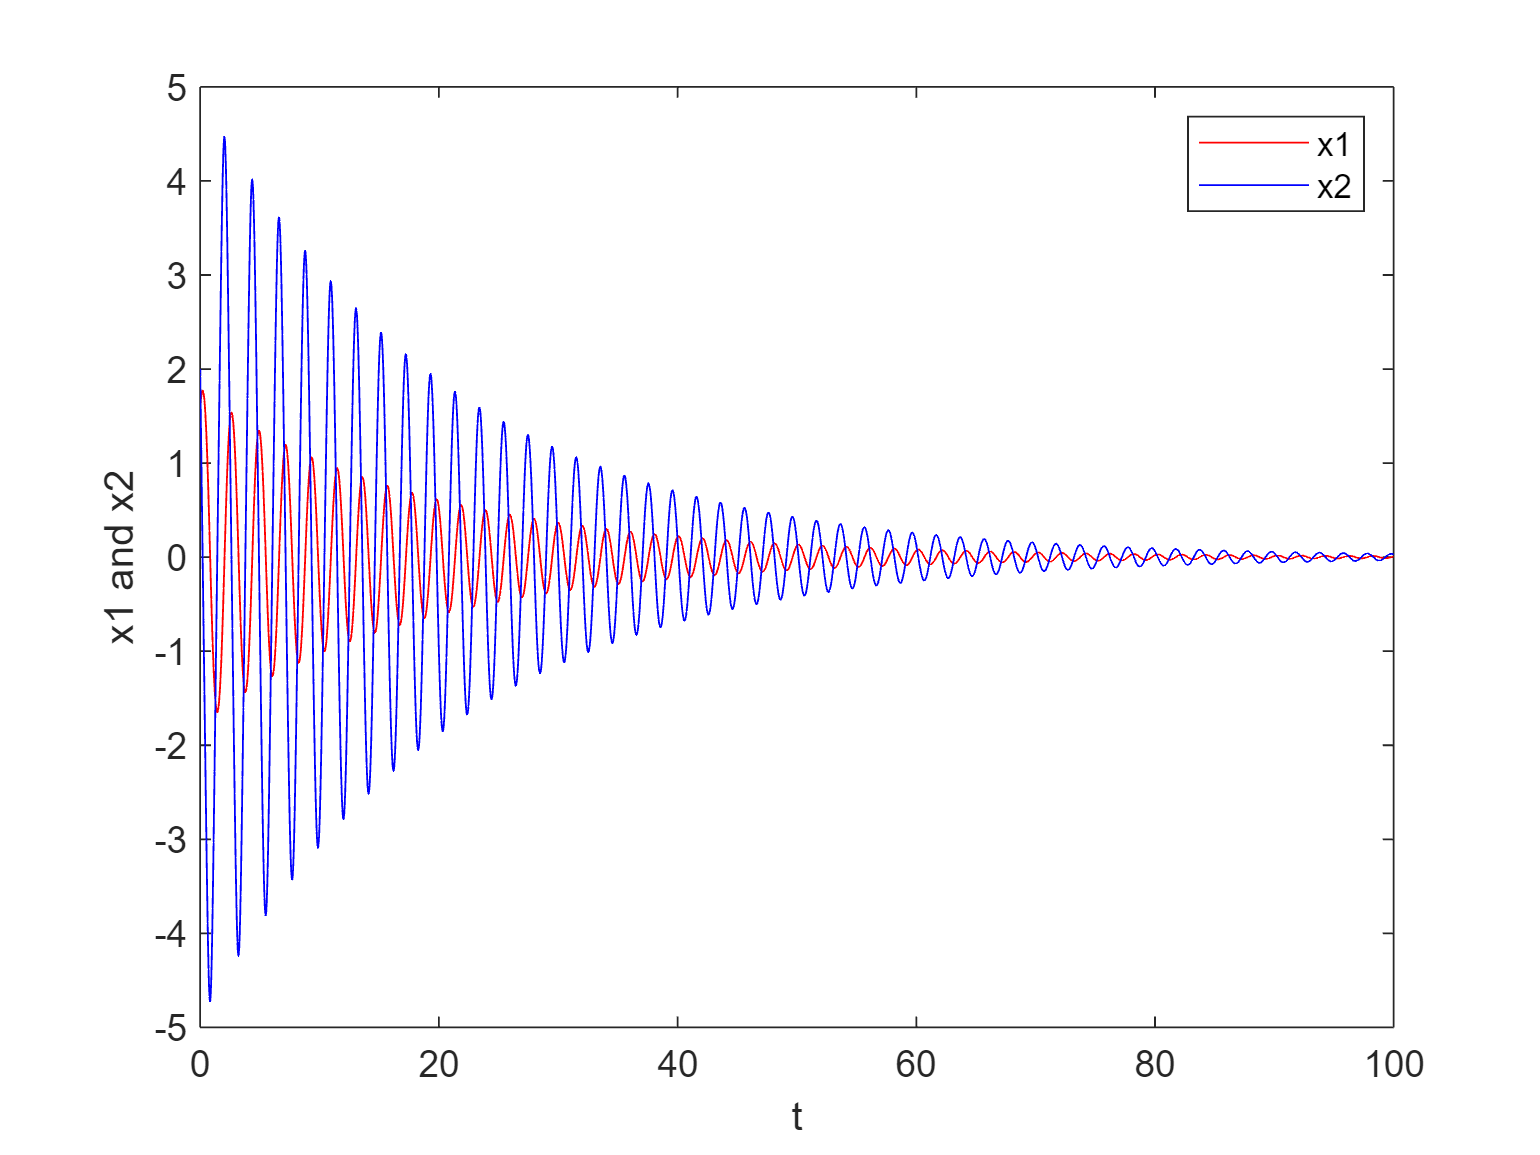

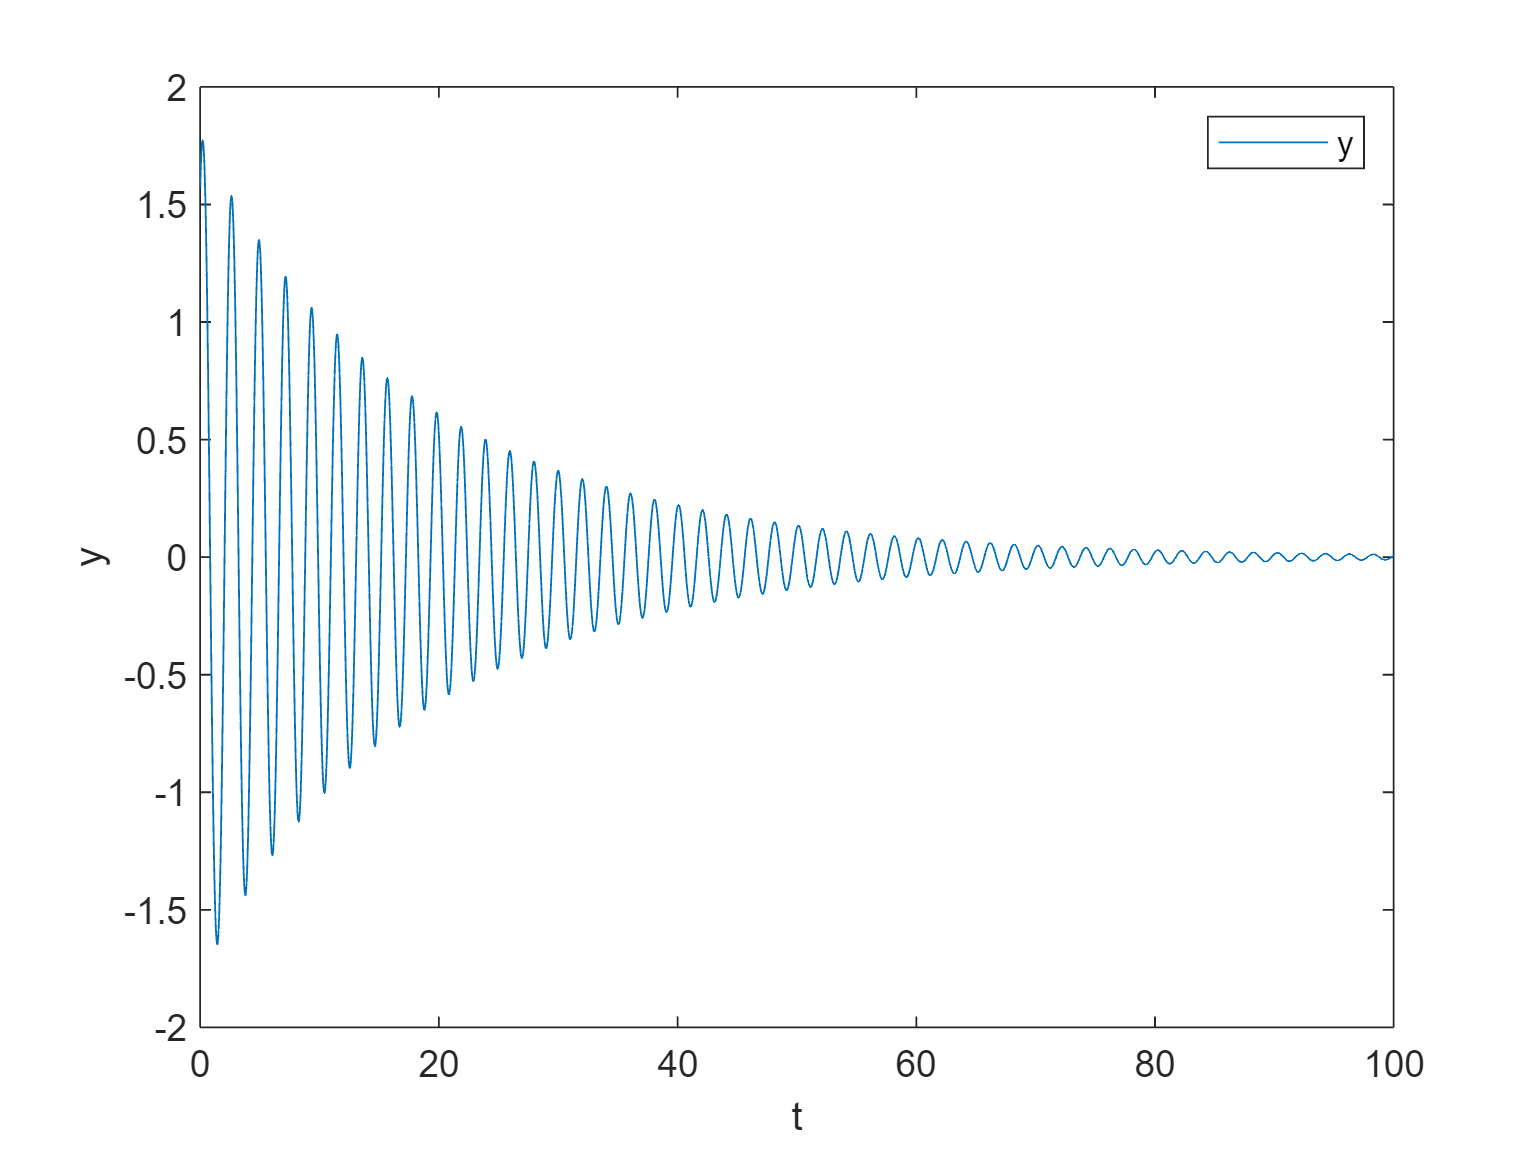

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Nel terzo caso, partiamo da una situazione iniziale diversa per la posizione del pendolo, in questo caso $ \frac{\pi}{2}$, e per la velocità condizione iniziale pari a $2$. Dato che il punto $[0, 0]
$ è un fuoco attrattivo, il sistema tenderà a raggiungere il punto di equilibrio, oscillando fino a convergenza, ma data la velocità iniziale diversa da $0$, il pendolo tenderà prima a salire e poi a raggiungere il punto di equilibrio.

Un ulteriore analisi:

x1=pi;
x2=0;
u=0;
simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

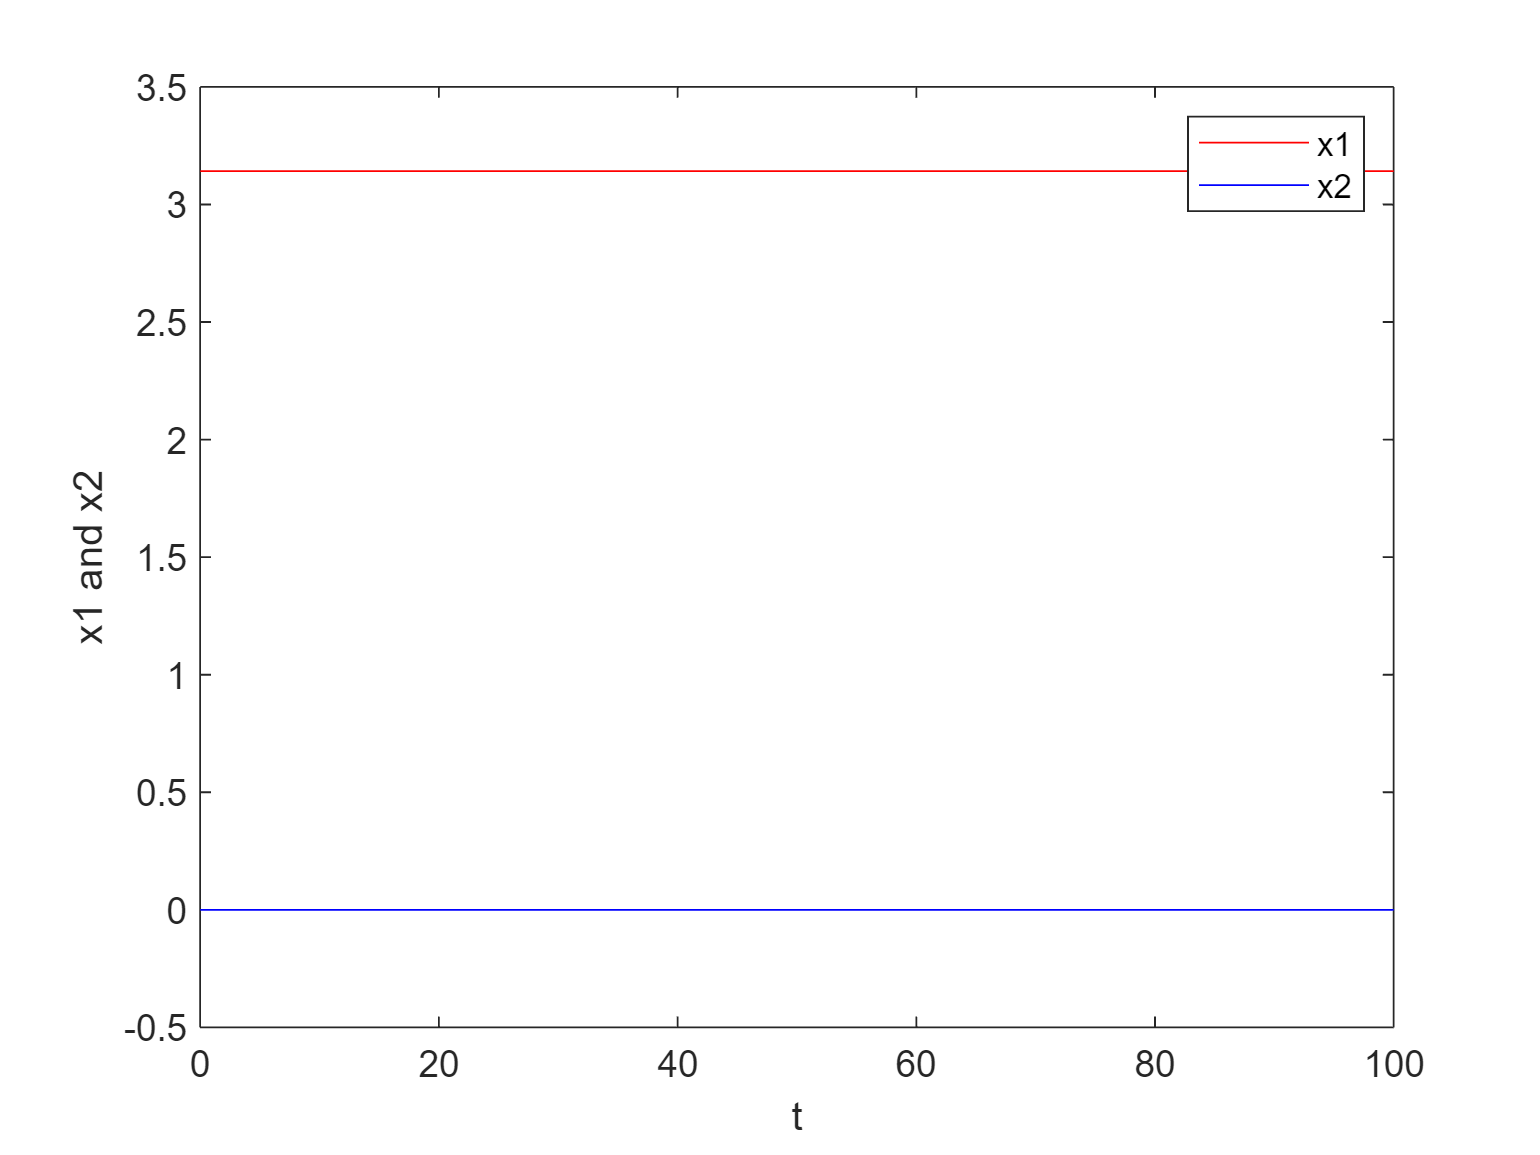

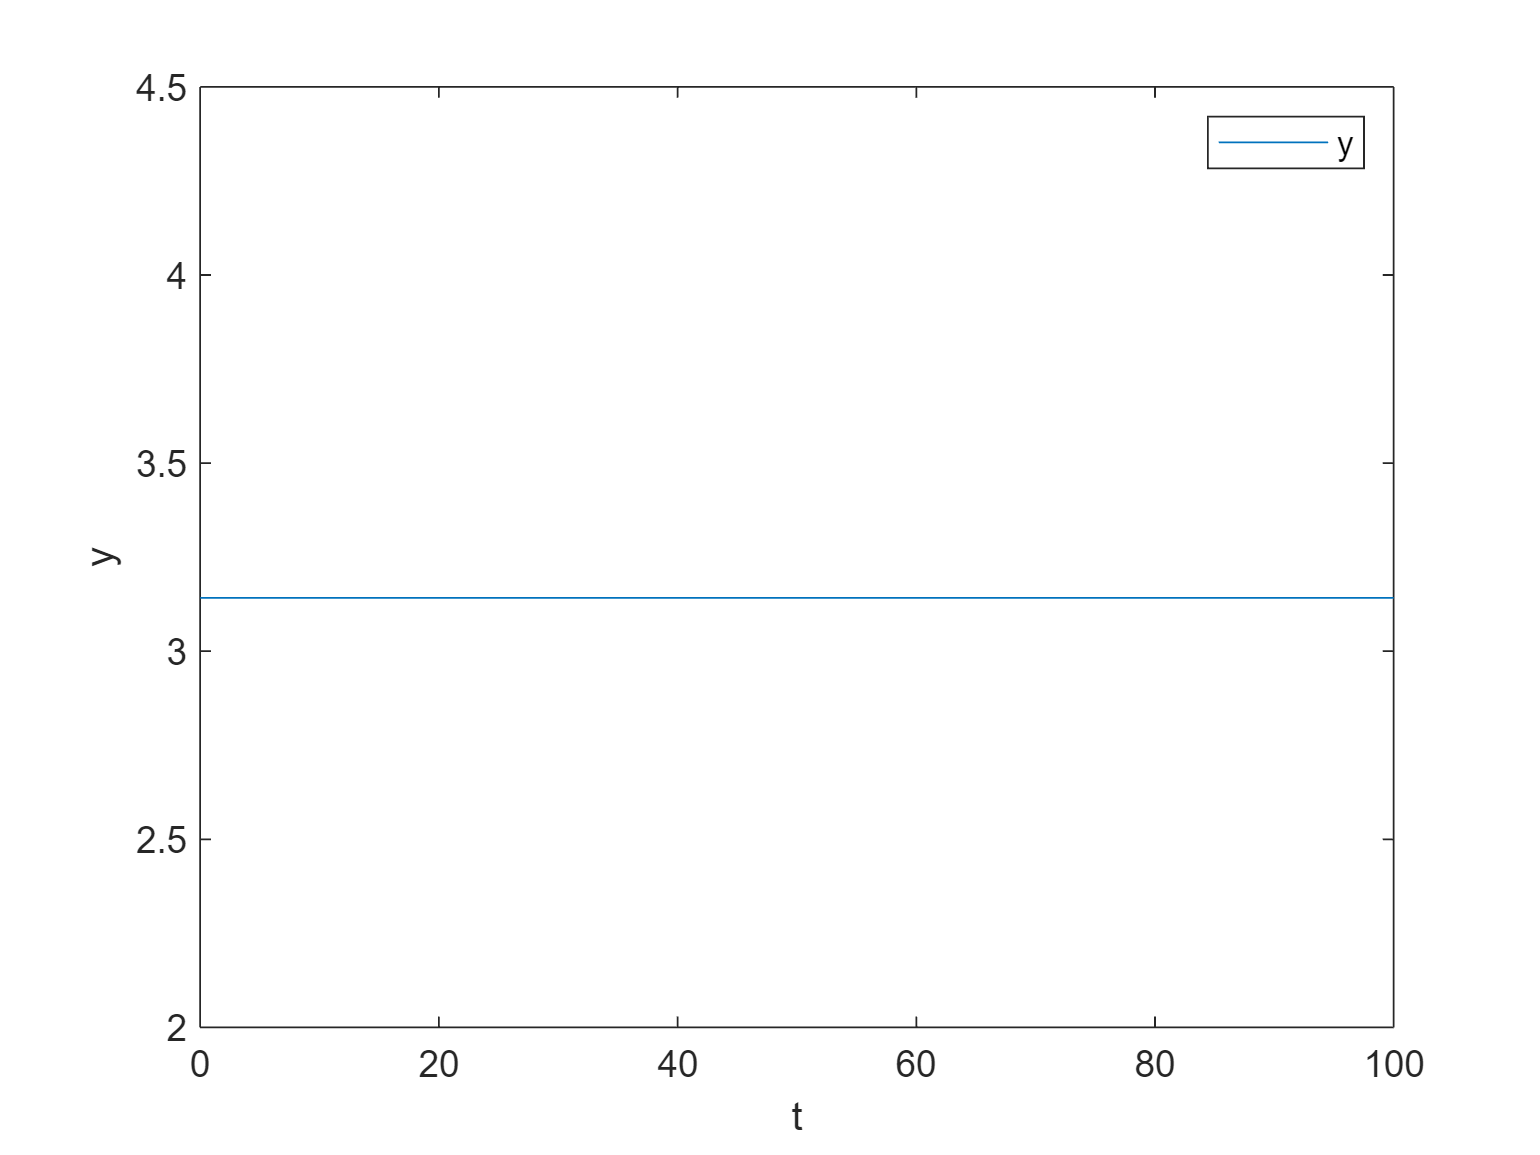


% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Nel quarto caso, partiamo da una situazione iniziale diversa per la posizione del pendolo, in questo caso $\pi
$, esattamente la posizione del punto di equilibrio instabile, e per la velocità, la condizione iniziale è pari a $0$. Dato che il punto $[\pi,0]
$ è un punto instabile, ma comunque di equilibrio, senza sollecitazioni esterne il sistema tende a restare nel punto di equilibrio (con le dovute tolleranze del calcolatore).

Infine, un'ultima analisi:

x1=pi;
x2=1;
u=0;
simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

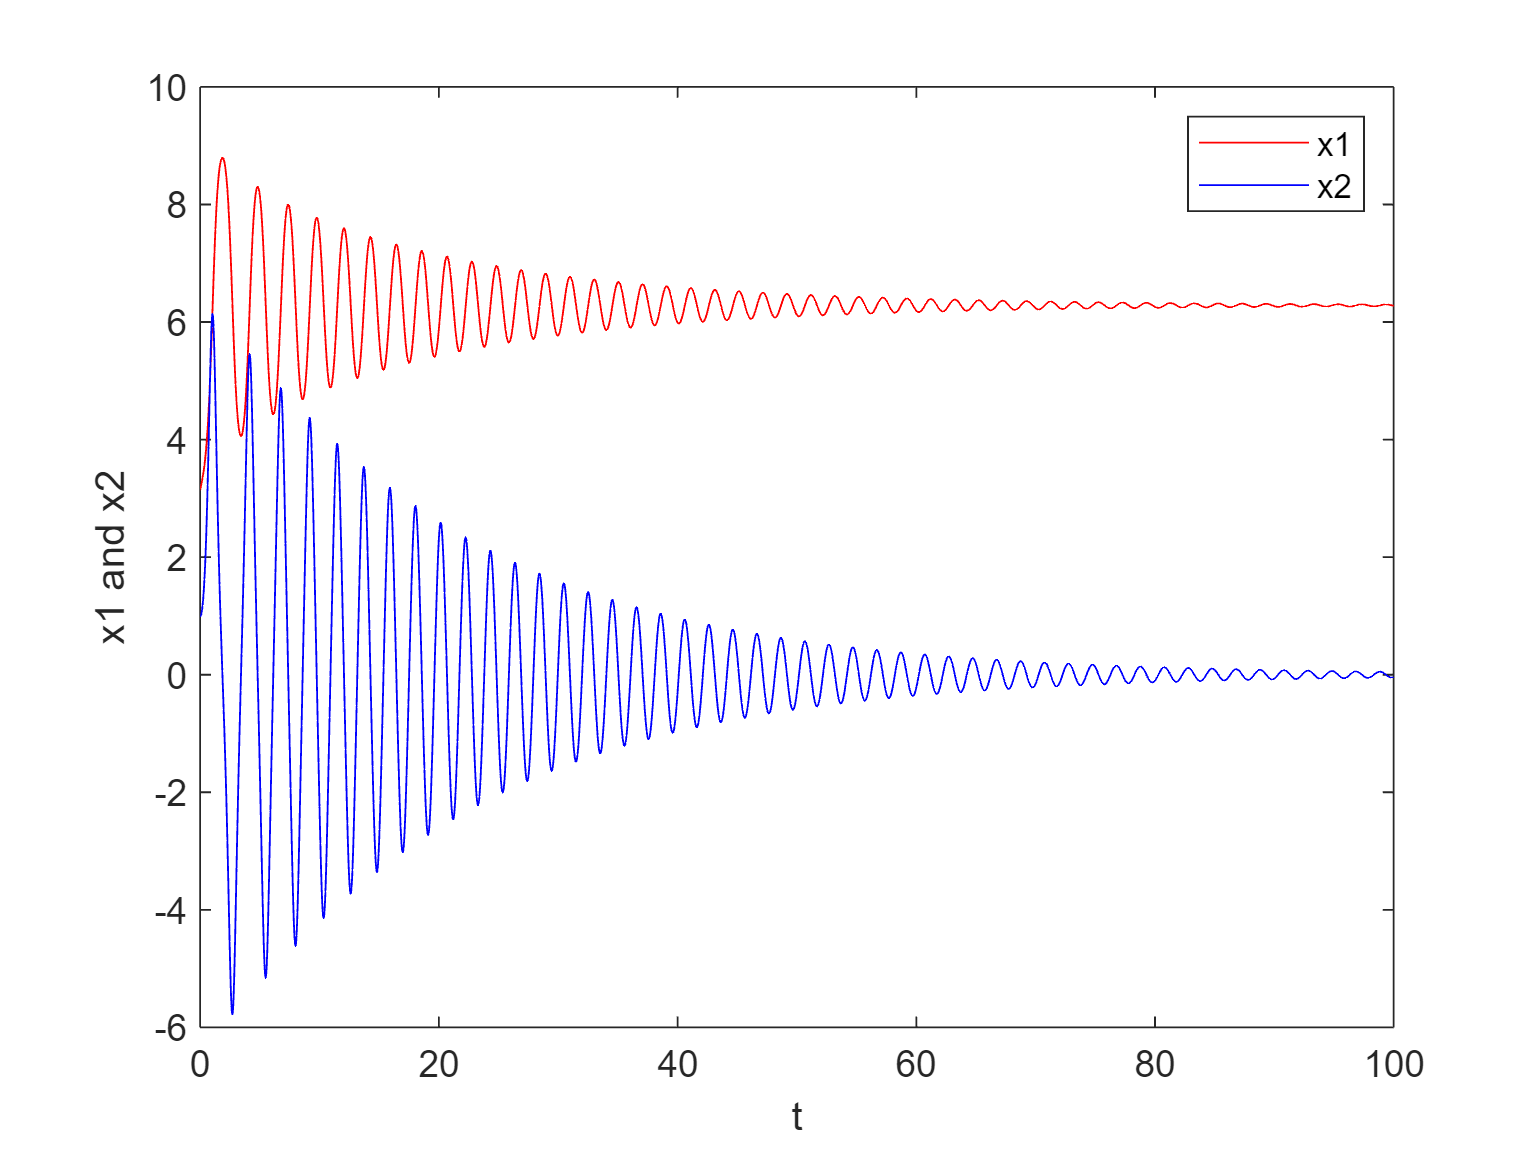

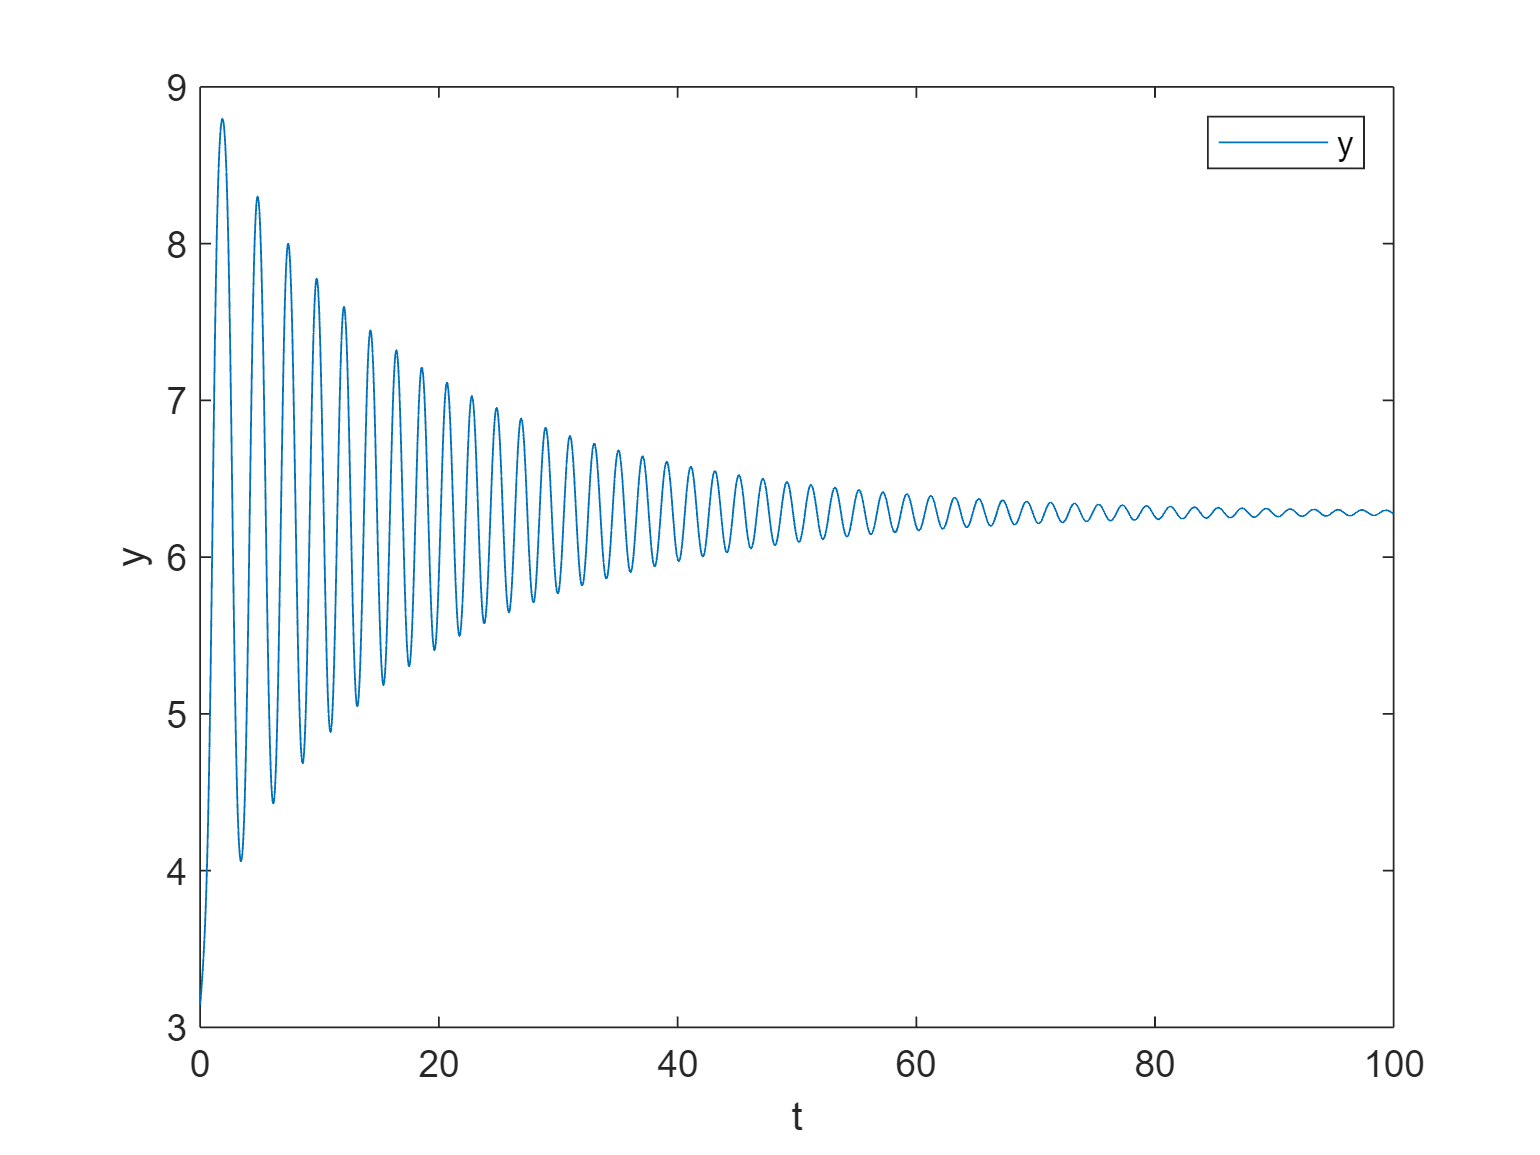


% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Nel quinto caso, partiamo da una situazione iniziale diversa per la posizione del pendolo, in questo caso $\pi$, esattamente la posizione del punto di equilibrio instabile, e per la velocità condizione iniziale pari a $1$. Dato che il punto $[\pi, 0]
$ è un punto instabile, il sistema tende a uscire da tale condizione iniziale e a raggiungere il punto di equilibrio stabile, oscillando fino a convergenza, ma data la periodicità del sistema, il punto di equilibrio stabile raggiunto è il fuoco attrattivo $[2\pi,0]
$ che fisicamente rappresenta lo stesso punto di quello $[0,0]
$. 

## Ulteriore analisi

Un ulteriore analisi, che poi si riflette nell'approccio con il piano delle fasi, è la verifica di ciò che avviene per i punti di equilibrio al variare di $u(t)$. Nell'analisi che segue è scelta costante, di conseguenza si parla di $u$ (il file simulink utilizzato è ancora **open_loop**, ma in questo caso introduciamo una $u$ costante):

x1=0;
x2=1;
u=2;
simOut = sim('open_loop.slx', 'SimulationMode', 'normal');

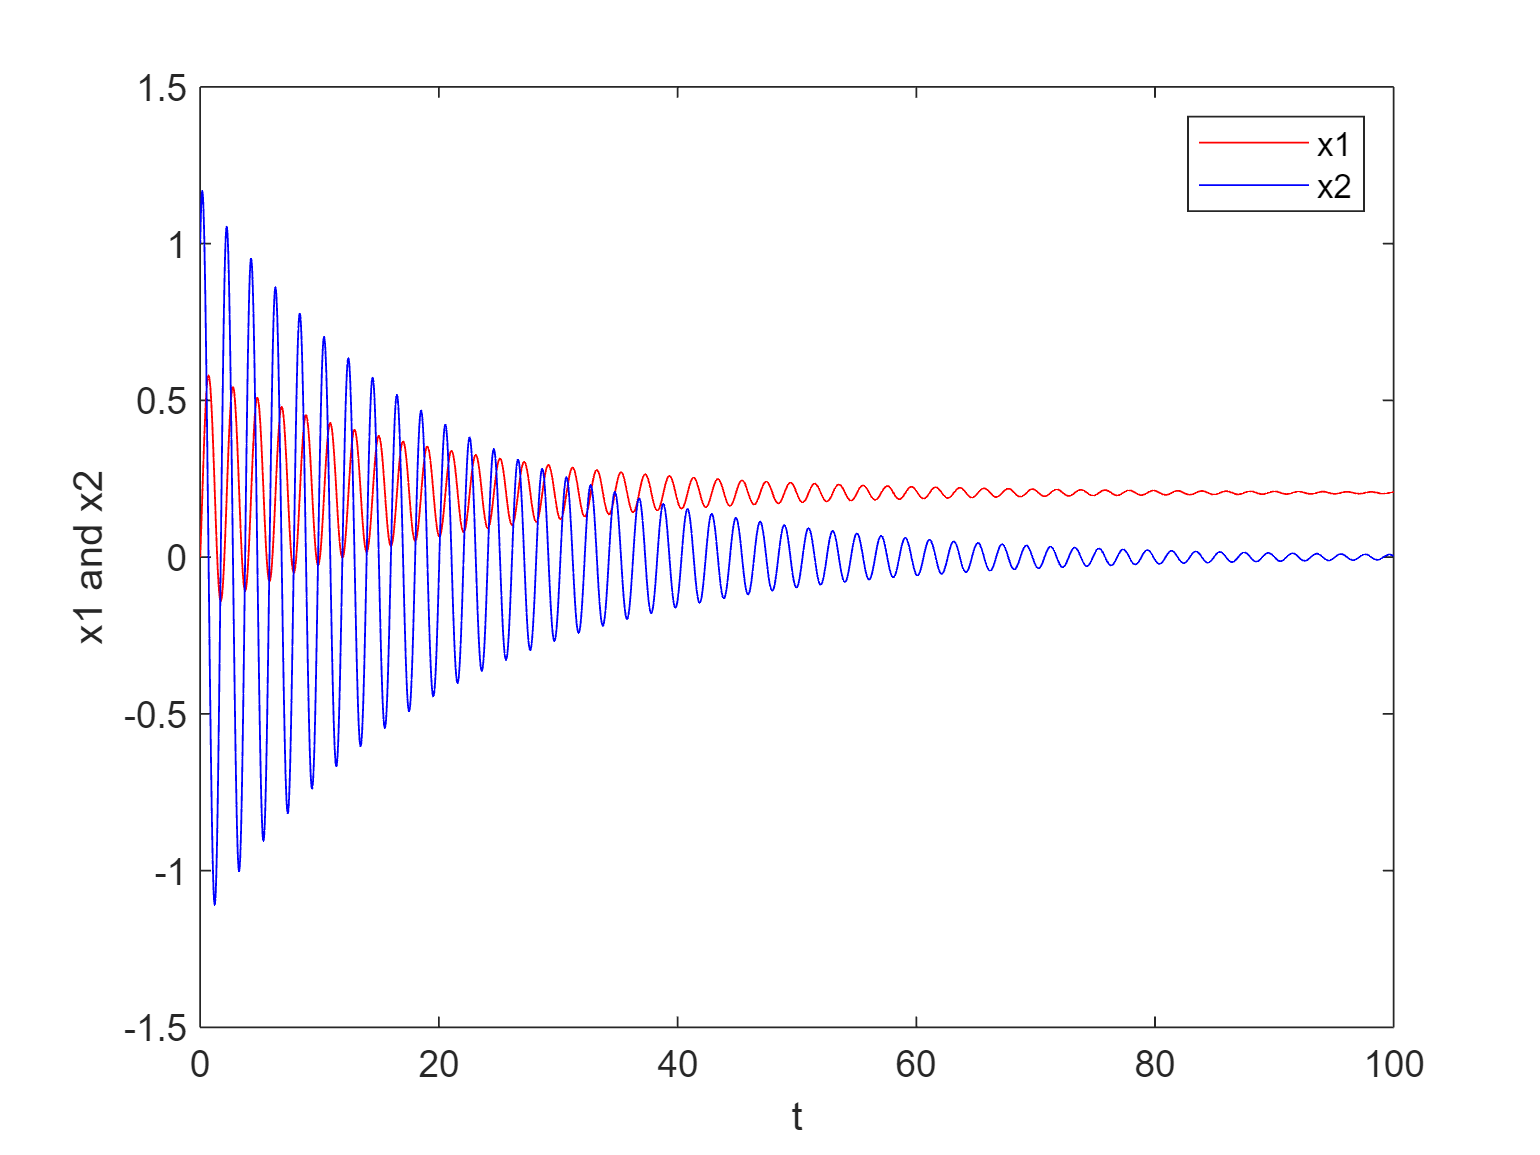

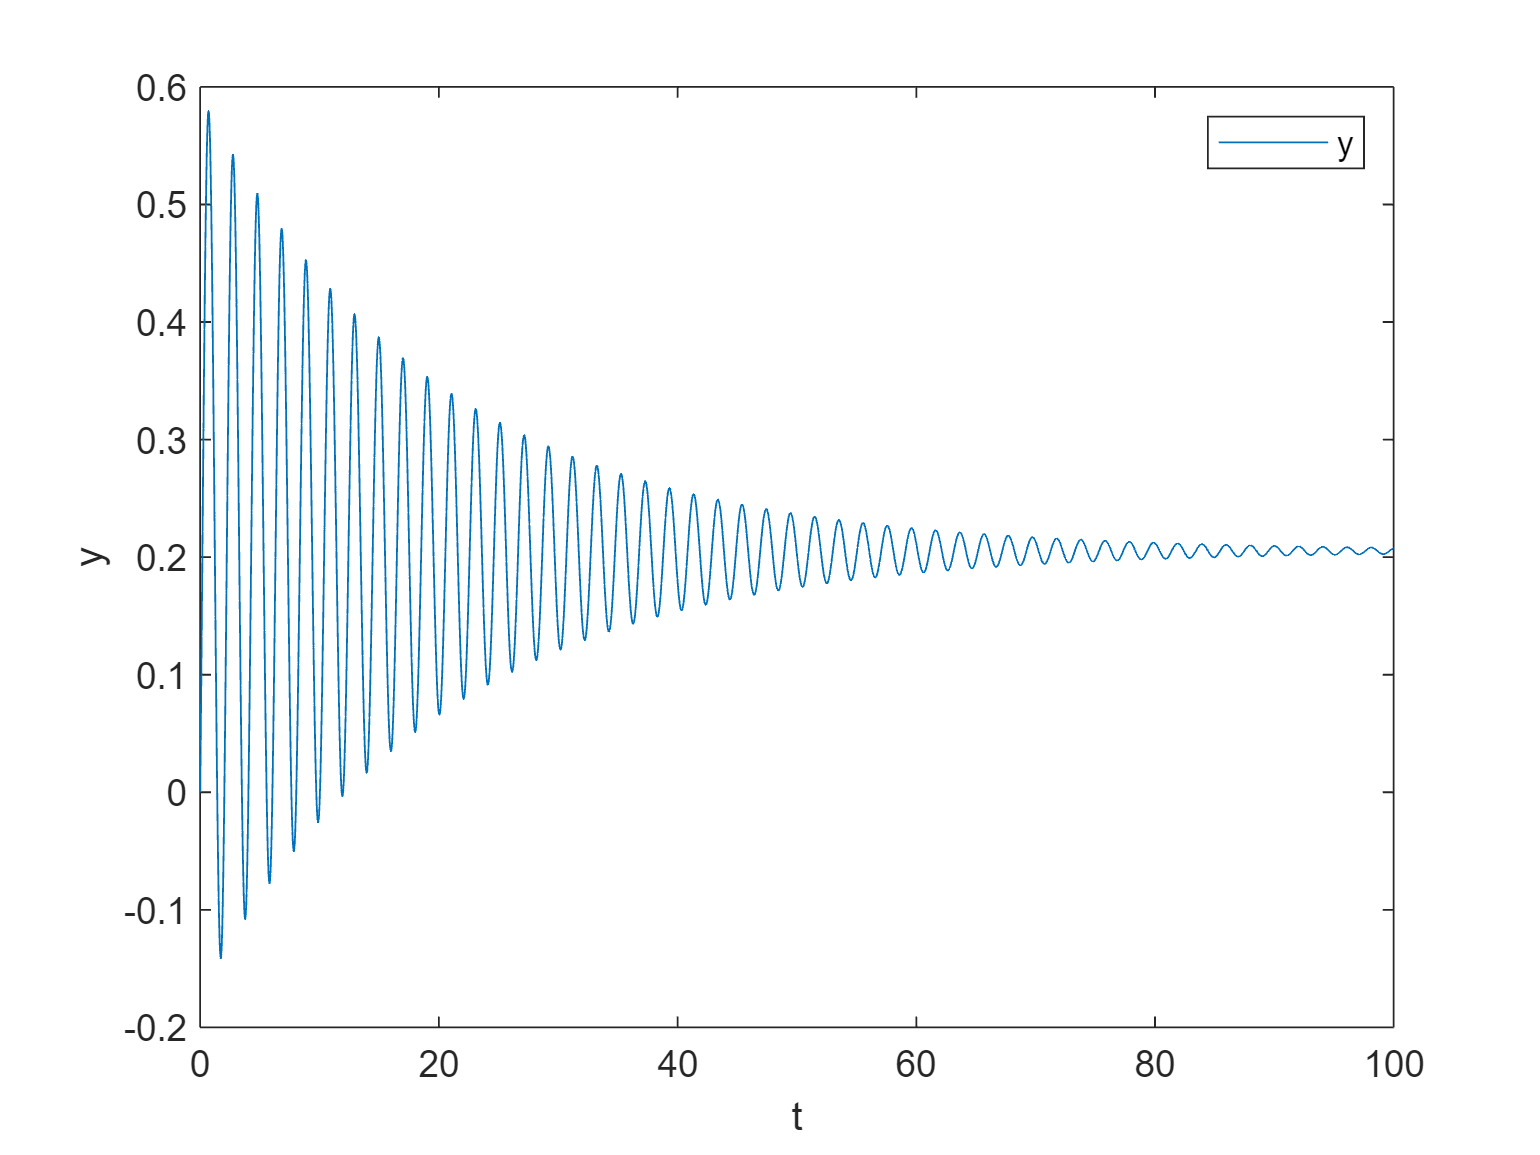

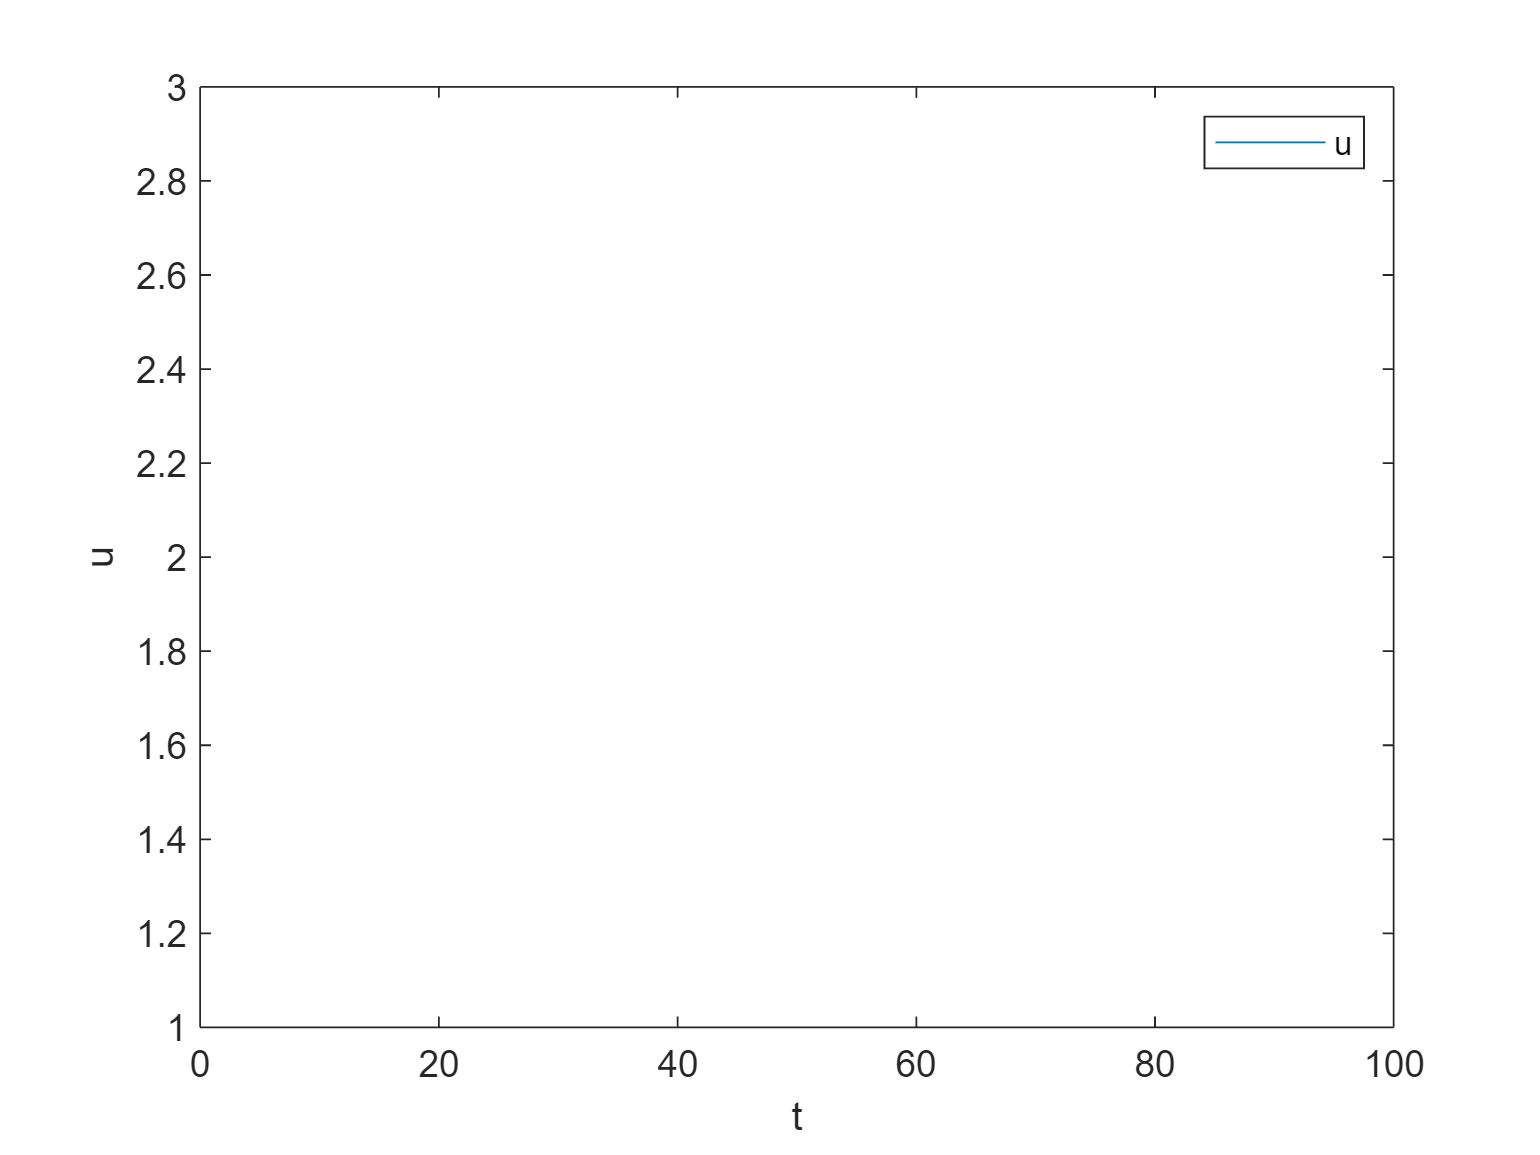


% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,0);

Ovviamente, dato che il punto di equilibrio del sistema dipende dall'ingresso di controllo, al variare di esso, varierà anche il punto di equilibrio 


$$x_{1_{eq}} =\arcsin {(\frac{g\ u(t)}{ml}}) \space\space\space x_{2_{eq}}=0$$


In questo caso il sistema oscilla fino a raggiungere il nuovo punto di equilibrio stabile.

## Piano delle fasi al variare di u, costante

Per analizzare il sistema, plottiamo il piano delle fasi per diversi ingressi, tra cui quello intorno al quale è stato linearizzato il sistema:

close all

tspan = [0 100];  % intervallo di simulazione
x0_1 = 0;
x0_2 = 1; 
x0 = [x0_1 x0_2];

u_values = [0,2,4,6];  

results = cell(1, length(u_values));

% Utilizzeremo il solver 'ode45' 
for i = 1:length(u_values)
    u = u_values(i);
    [t, x] = ode45(@(t, x) function_ode_WP1(t, x, u), tspan, x0);
    results{i} = x;  
end

% Plot delle traiettorie nel piano delle fasi
figure();
hold on;
colors = 'bgrm'; 
for i = 1:length(u_values)
    x = results{i};
    plot(x(:,1), x(:,2), colors(i));
end

xlabel('x1');
ylabel('x2');
legend('u = 0', 'u = 1', 'u = 2', 'u = 3');
grid on;

Come notiamo, i punti di equilibrio dipendono dall'azione di controllo, al variare della quale i punti di equilibrio del sistema varia. Lo stesso risultato è ottenibile attraverso lo studio del piano delle fasi per diverse traiettorie con l'aiuto di pplane e dell'app "Phase Plane", un pacchetto aggiuntivo di Matlab per visualizzare punti di equilibrio, le nullclines e le traiettorie nel piano delle fasi

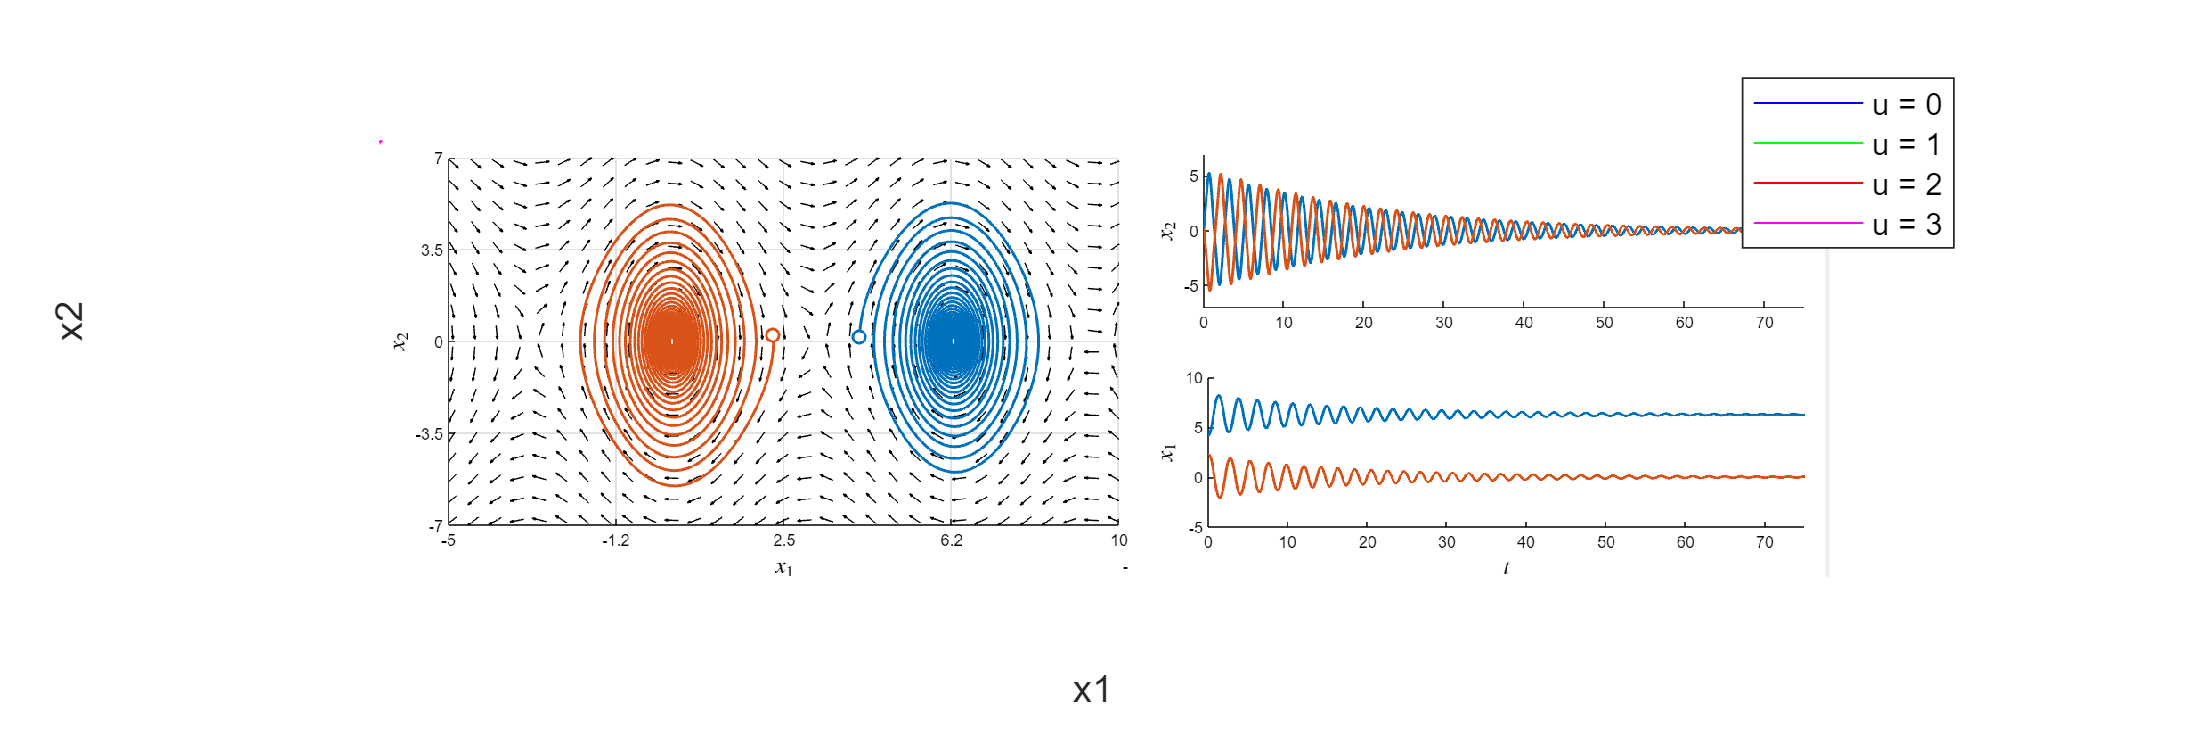

imshow(imread("img/short_distance.png"))

Si effettua un plot dei punti di equilibrio del sistema, considerando $u=0$, essi sono periodici di periodo $2\pi
$e a partire da condizioni iniziali differenti, raggiungerà uno di questi punti di equilibrio (caso estremo, la partenza dal punto di equilibrio instabile, ma nella realtà fisica, una minima deviazione da questo punto porterebbe comunque il sistema al punto di equilibrio stabile). Dal grafico è possibile apprezzare l'esempio di due traiettorie che partono da condizioni iniziali $[x_1,x_2]
$ differenti e che raggiungono punti di equilibrio diversi, seppur fisicamente accomunabili alla situazione in cui la mensola è verso il basso.

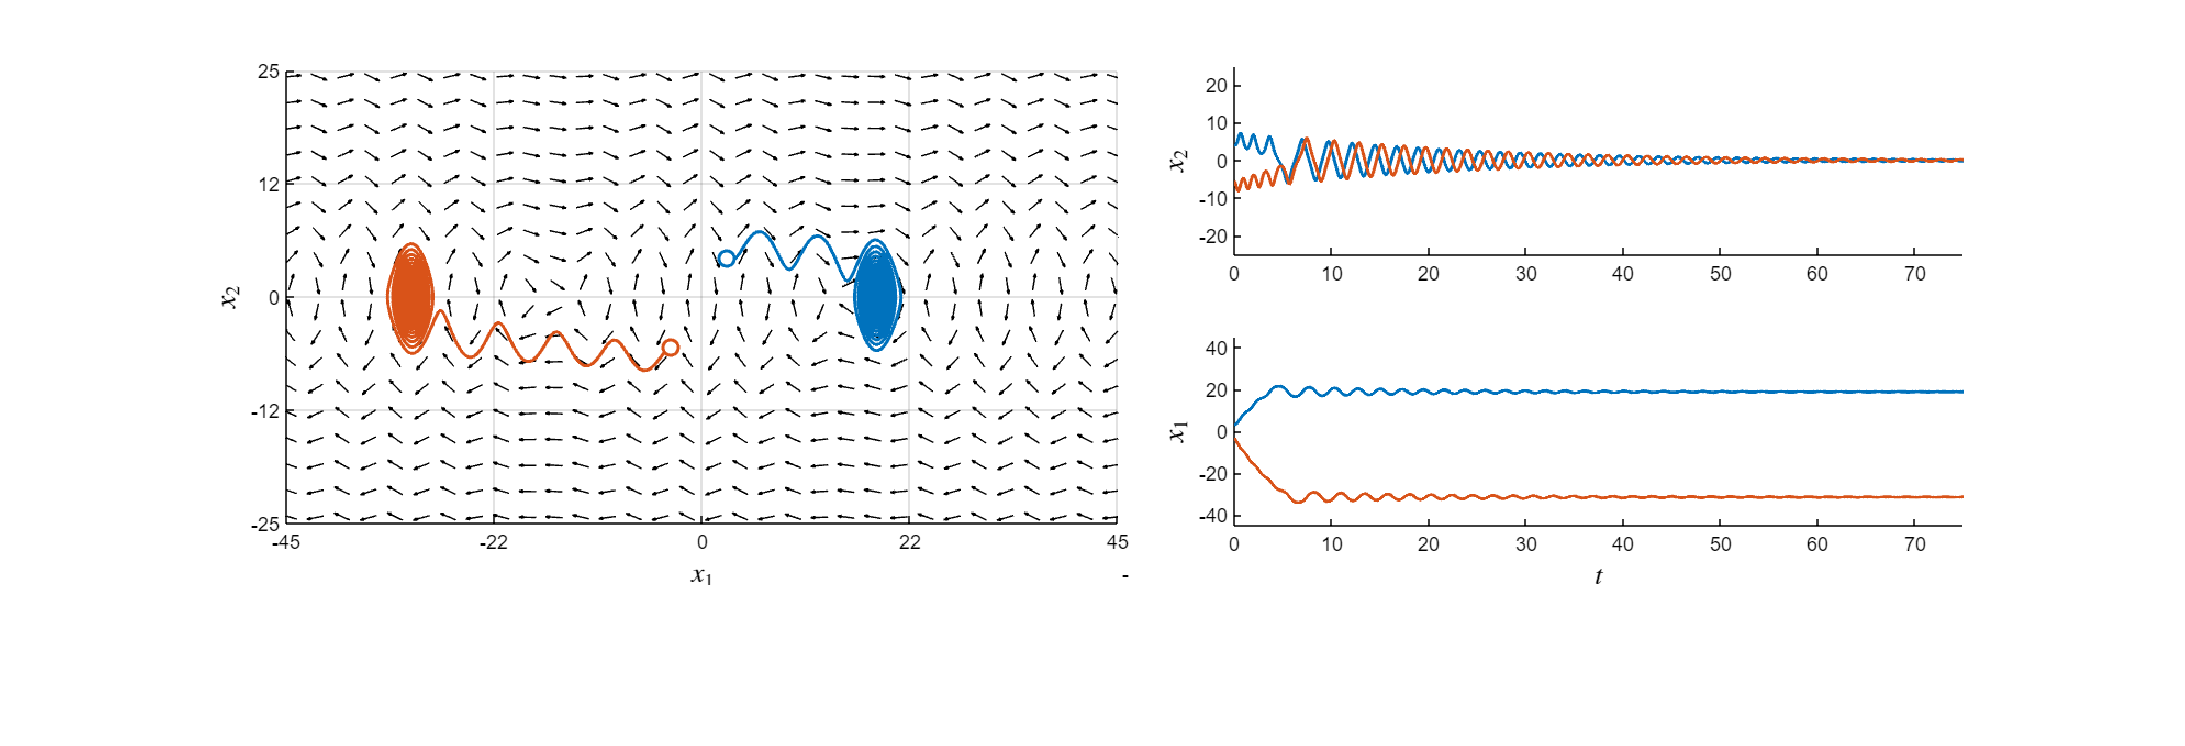

imshow(imread("img/long_distance.png"))

Lo stesso grafico è ottenibile con scalatura minore, e si fa notare come, a partire da condizioni iniziali in cui anche la velocità è non nulla, ciò che differisce dal caso precedente è che il sistema tende a compiere più giri completi prima di assestarsi nel punto di equilibrio a causa della velocità iniziale che possiede, ovviamente maggiore è la velocità più giri effettuerà rispetto alla posizione attuale e si stabilizzerà in un punto di equilibrio con periodicità più elevata all'aumentare del numero di giri effettuati.

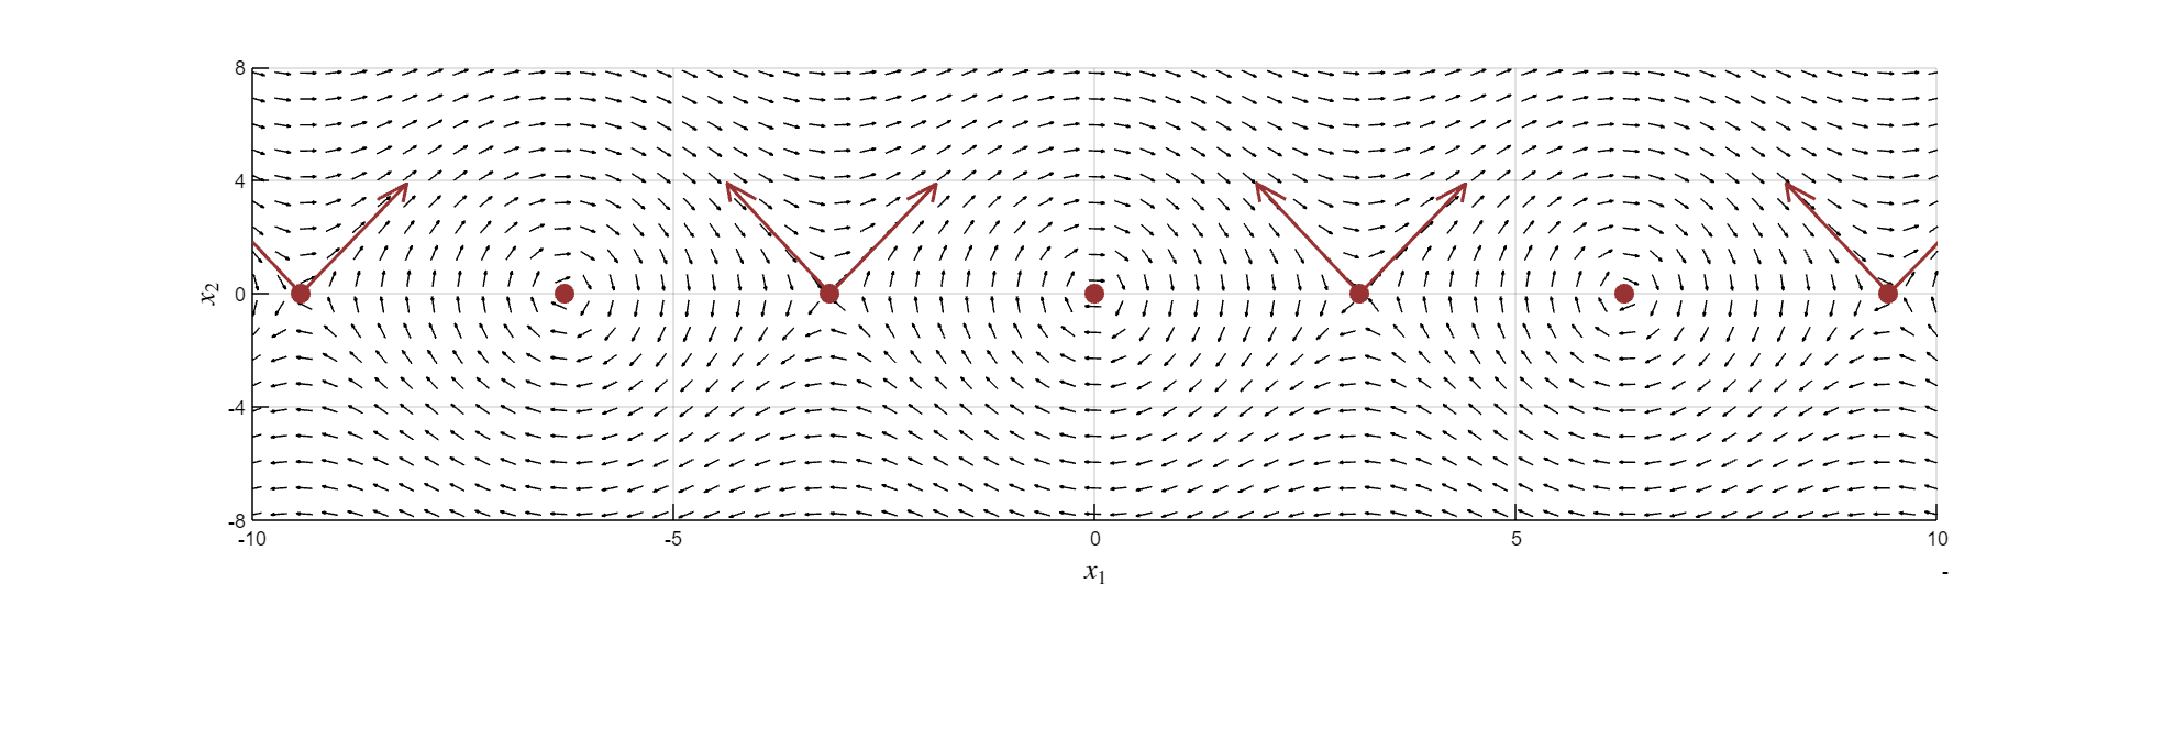

imshow(imread("img/equilibria.png"))

Dallo stesso strumento, **Phase Plane, **è possibile visualizzare graficamente i punti di equilibrio del sistema, che come descritto in precedenza, sono di due tipi e sono periodici di periodo $2\pi
$, il primo è $[0,0]+2k\pi
$ed è un punto di equilibrio di tipo fuoco attrattivo, stabile, come è possibile apprezzare sia dal fatto che non sono rappresentati tramite le frecce in rosso, sia da come il piano mostra come i punti tendono a quel punto, e $[\pi,0]+2k\pi$è un punto di equilibrio instabile evidenziato dalle frecce in rosso.

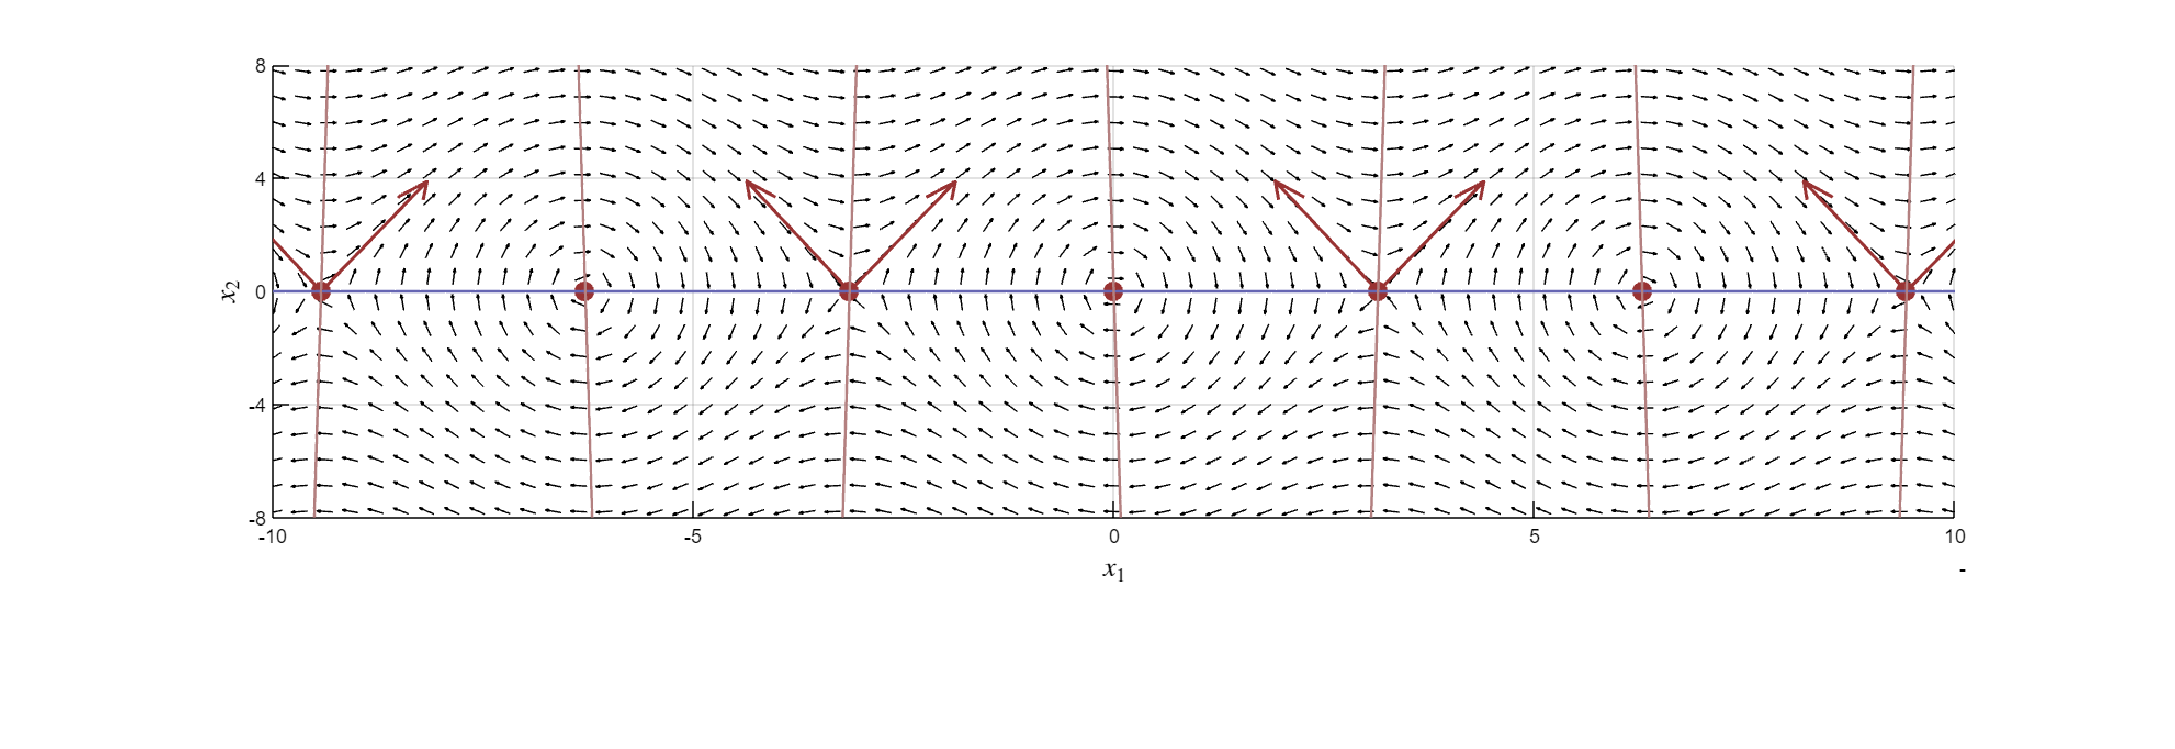

imshow(imread("img/nullclines.png"))

Ulteriore possibilità è la visualizzazione delle nullclines, le loro intersezioni rappresentano, nei sistemi dinamici, punti critici o punti stazionari del sistema, ovvero punti in cui il sistema non varia nel tempo, infatti, come si può notare, si intersecano nei punti di equilibrio descritti in precedenza. La relativa posizione delle nullclines può suggerire, infatti, come le variabili evolvono nel tempo intorno a tali punti critici, ad esempio, se convergono o divergono.

## Analisi dei punti di equilibrio con il piano delle fasi e linarizzazione del sistema intorno al punto di equilibrio di nostro interesse

Un sistema linearizzato generale sarà nella forma:


$$\dot \delta x =\left[ \begin{array}{c}  \frac{df_1}{dx_1} &...&\; \frac{df_1}{dx_n} \\ ... & ...& ... \\ \frac{df_n}{dx_1} &...&\; \frac{df_n}{dx_n} \end{array} \right]  \delta x+ \left[ \begin{array}{c} \frac{df_1}{du_1} &...& \frac{df_1}{du_n}\\...&...&...\\  \frac{df_n}{du_1}& ...&\frac{df_n}{du_n}\end{array} \right]\delta u
$$



$$\delta y = \left[\begin{array}{c} \frac{dg_1}{dx_1} &...&\; \frac{dg_1}{dx_n} \\ ... & ...& ...\\ \frac{dg_n}{dx_1} &...&\; \frac{dg_n}{dx_n}\end{array}\right]\delta x+\left[\begin{array}{c} \frac{dg_1}{du_1} &...& \frac{dg_1}{du_n}\\...&...&...\\  \frac{dg_n}{du_1}& ...&\frac{dg_n}{du_n}\end{array}\right]\delta u$$


Quindi partendo dal nostro sistema:


$$\left\{ 
    \begin{array}{l}
        \dot x_1 = x_2
        \\\dot x_2= -\frac {g}{l} sin(x_1) - \frac {b}{ml^2} x_2 + \frac{u(t)}{ml^2} 
        \\ y=x_1
    \end{array} 
\right.
$$


possiamo ricavare i punti di equilibrio ponendo le due equazioni pari a $0
$:


$$\left\{
\begin{array}{l} x_2 = 0
\\-\frac{g}{l}sin(x_1)-\frac{b}{ml^2}z_2+\frac{u(t)}{ml^2} = 0
\end{array}
\right.$$


Considerando $u_e=0
$ come da traccia, otteniamo:


$$\left\{
\begin{array}{l} x_2 = 0
\\sin(x_1)= 0
\end{array}
\right.$$


I punti di equilibrio risultanti, come già graficamente verificato precedentemente, sono $[0,0] \space \text{e} \space [\pi,0]
$ con relativa periodicità. A noi interessa la linearizzazione intorno al punto di equilibrio $[\pi,0]
$. Definiamo $z = x- x_e \space \text{e} \space v=u-u_e$ con $x_e = [\pi,0]
$ e $u_e = 0
$, il sistema è riscrivibile nella forma:


$$\left\{ 
    \begin{array}{l} \dot{z_1} =z_2
\\ \dot{z_2}=-\frac{g}{l}sin(z_1+x_e)-\frac{b}{ml^2}z_2+\frac{v(t)}{ml^2}
    \end{array} 
\right.$$


Per linearizzare il sistema intorno al punto di equilibrio, bisogna trovare le matrici A,B,C,D, rispetto al punto di equilibrio desiderato.

La jacobiana risultante sarà $J=\left[\begin{array}{c} \frac{df_1}{dz_1} \; \frac{df_1}{dz_2} \\ \frac{df_2}{dz_1} \; \frac{df_2}{dz_2} \end{array}\right]=\left[\begin{array}{c} 0 & 1 \\ -\frac{g}{l}cos(z_1+x_e) & -\frac {b}{ml^2} \end{array}\right]_{|_{z=z_a}}=\left[\begin{array}{c} 0 & 1 \\9.81 & -0.1 \end{array}\right] = A$


$$\left[\begin{array}{c} \frac{df_1}{dv} \; \\ \frac{df_2}{dv} \;  \end{array}\right]= B = \left[\begin{array}{c} 0 \; \\ 1 \;  \end{array}\right]$$


A questo punto, il controllore a retroazione di stato espresso in $z$, ossia per il sistema linearizzato, avrà la forma del tipo $v=-Kz+k_r r_l$. Antitrasformando il sistema nelle variabili di partenza si ha che:

$u-u_e=-K(x-x_e)+k_r(r_{nl}-\pi)$, in cui $\pi
$ rappresenta la differenza di riferimento tra il sistema linearizzato in $\pi
$, in cui inseguire $\pi
$implica restare nell’origine, e il sistema non lineare. $u_e=0, r_{nl}=\pi$ (il riferimento,da traccia, del sistema non lineare è $\pi$).

Di conseguenza otteniamo $u=-K_1x_1+K_1x_{e_1}-K_2x_2+K_2x_{e_2} + k_r0=-K_1x_1-K_2x_2+K_1\pi$.

Siccome $\pi$ è il riferimento, tale controllore è analogo ad un controllore a retroazione di stato, nella forma più generale possibile si ottiene:


$$u=-K_1x_1+K_1x_{e_1}-K_2x_2+K_2x_{e_2}+k_r(r-\pi)$$


A questo punto quindi si può affermare che inseguire il riferimento nullo nella versione linearizzata del sistema porta a inseguire il riferimento desiderato nel sistema non lineare.

%Scriviamo le Jacobiane del sistema linearizzato A,B,C,D pari a:
A=[0 1; 9.81 -0.1];
B=[0; 1];
C=[1 0];
D=0;

## Analisi del controllore v0 fornito da traccia

Proseguiamo con l'analisi del controllore fornito dalla traccia: $u=-K_1 x_1 - K_2 x_2 + K_1 \pi$ in cui: $K= [18235, 53.9]$ otteniamo quindi:

$u=-18235x_1 - 53.9 x_2 + 18235 \pi$, come specificato in precedenza, qui il termine $k_r$ scompare poichè moltiplicato per $0$.

Per simulare il comportamento del controllore sul sistema, è stato realizzato uno schema simulink per implementare la legge di controllo, è richiesta la retroazione di entrambe le variabili di stato, e dato che il sistema non lineare restituisce le derivate delle variabili di stato, c'è bisogno di integrarle per poi poterle rifornire al sistema in ingresso. Come specificato in precedenza il sistema è rappresentato da una funzione matlab a cui in ingresso diamo l'azione di controllo e le variabili di stato. Infine è stata implementata le legge di controllo con relative retroazione dello stato e moltiplicazione per i coefficienti proposti dalla traccia.

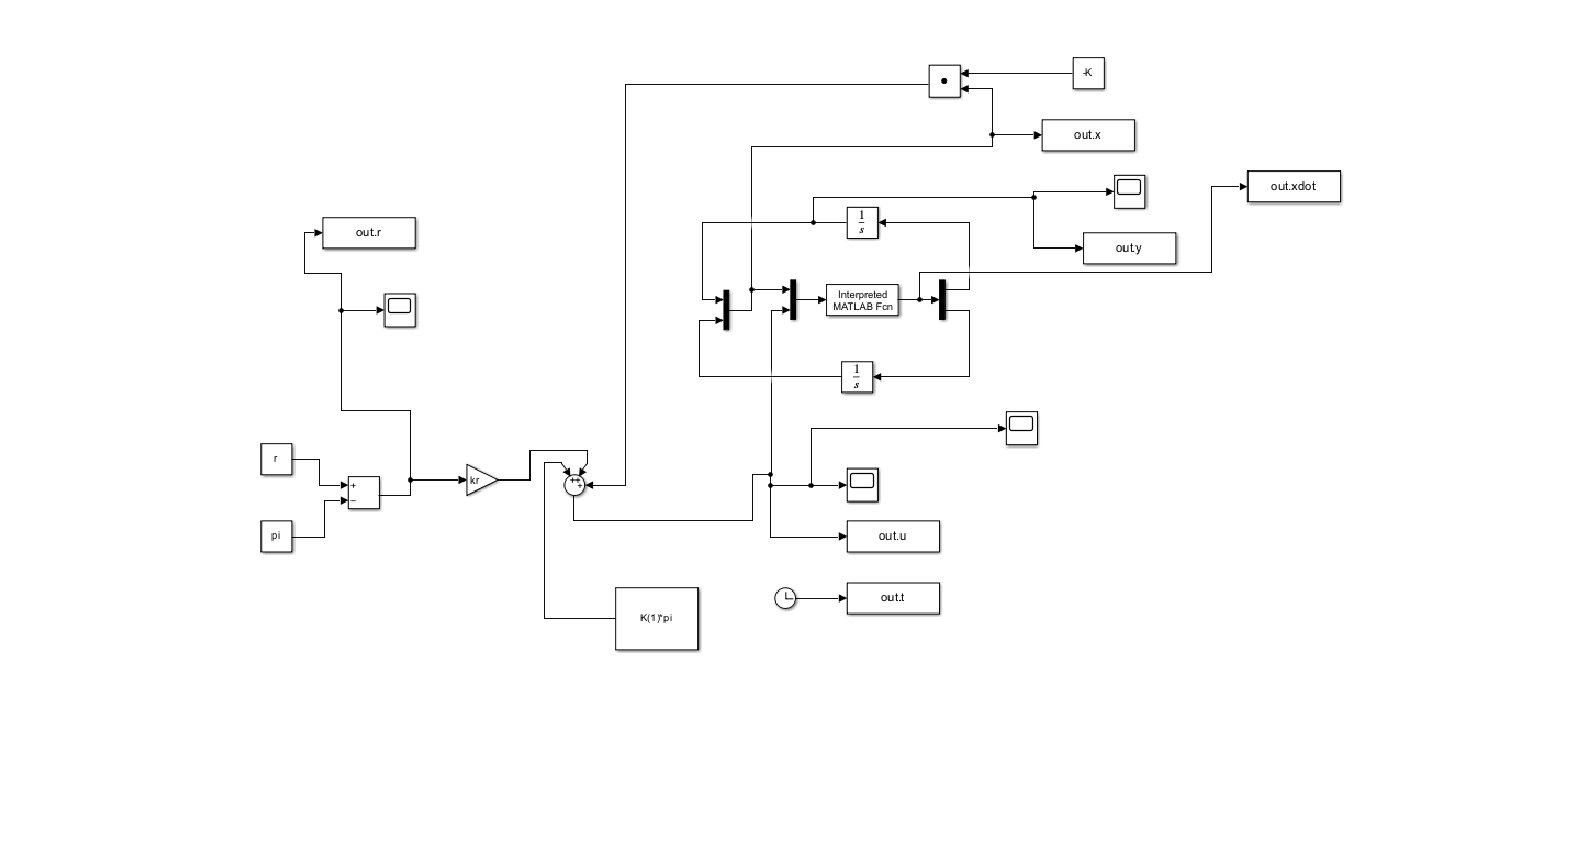

imshow(imread("img/v0scheme.png"))

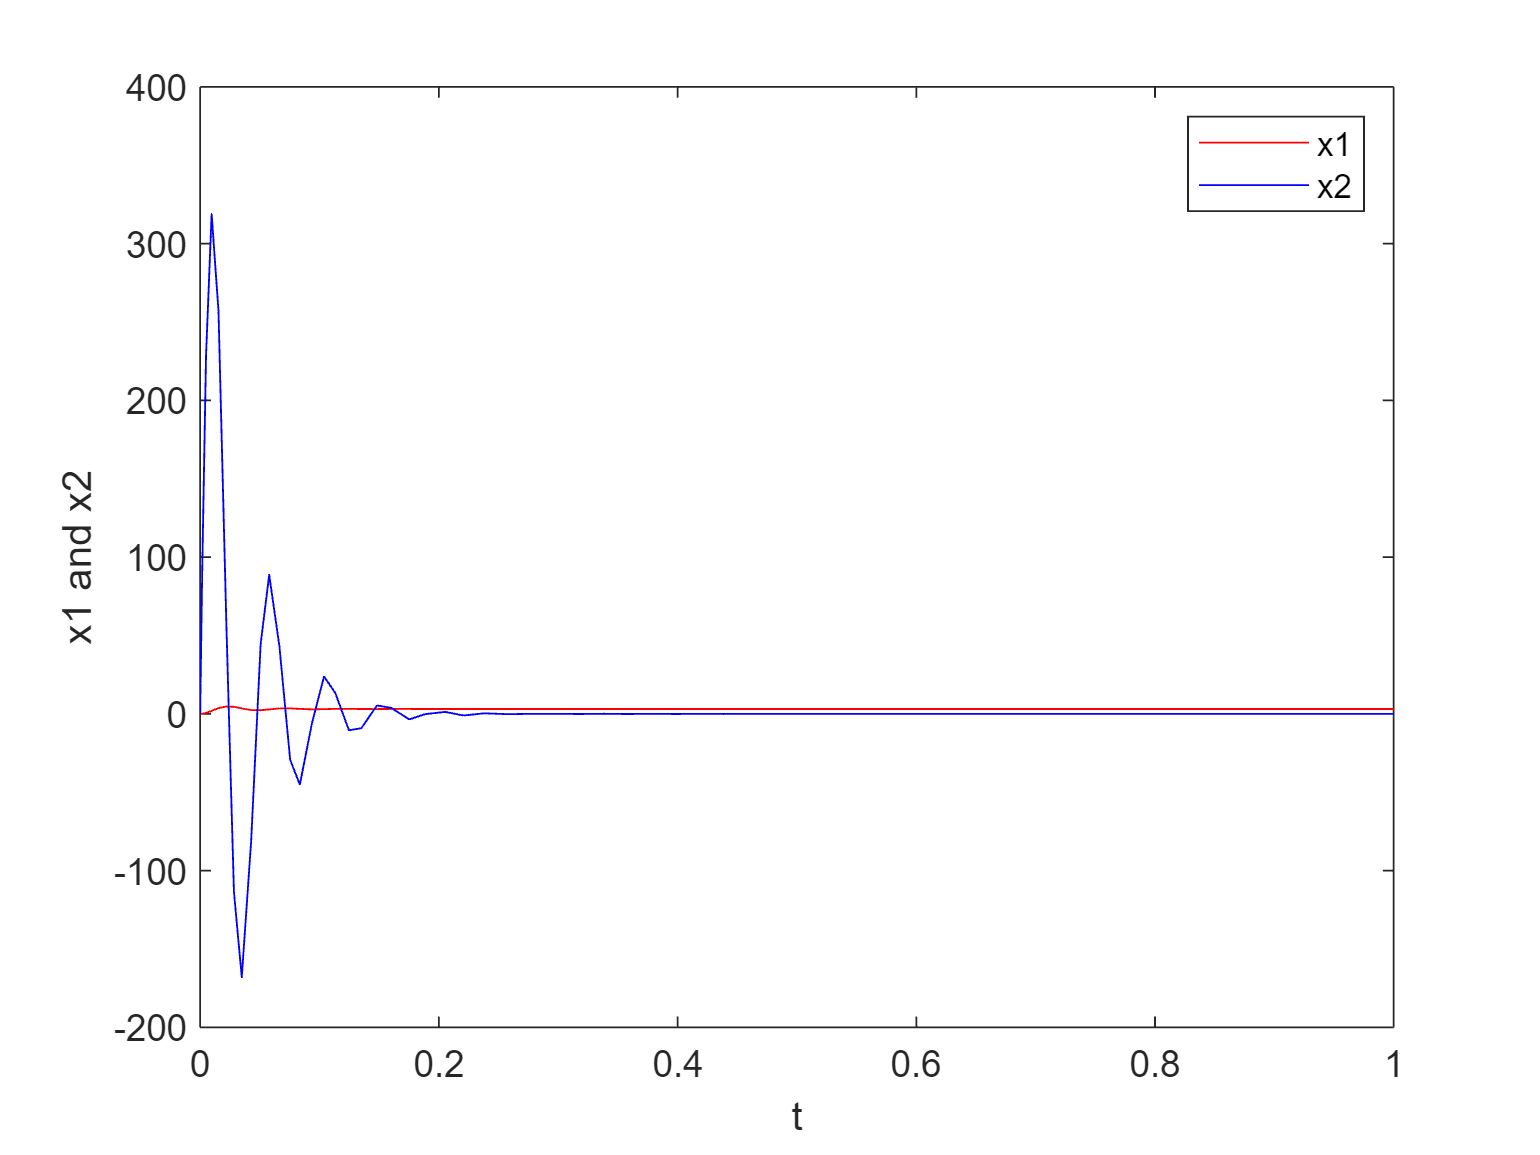

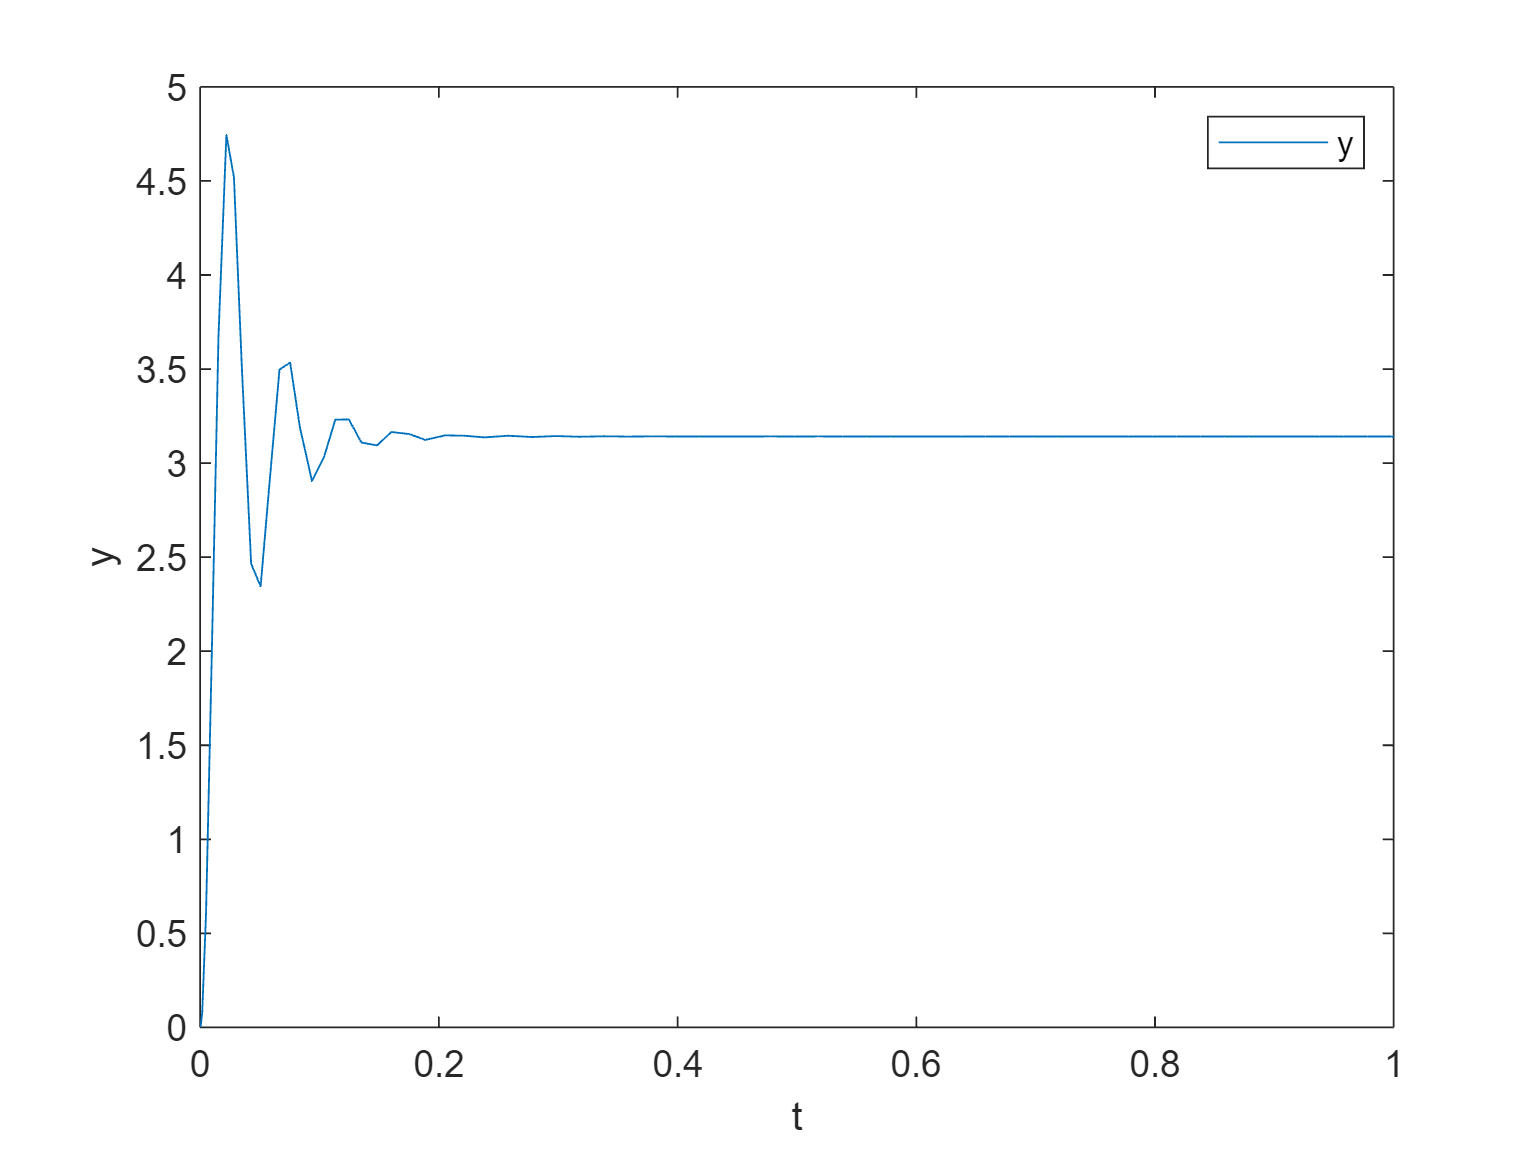

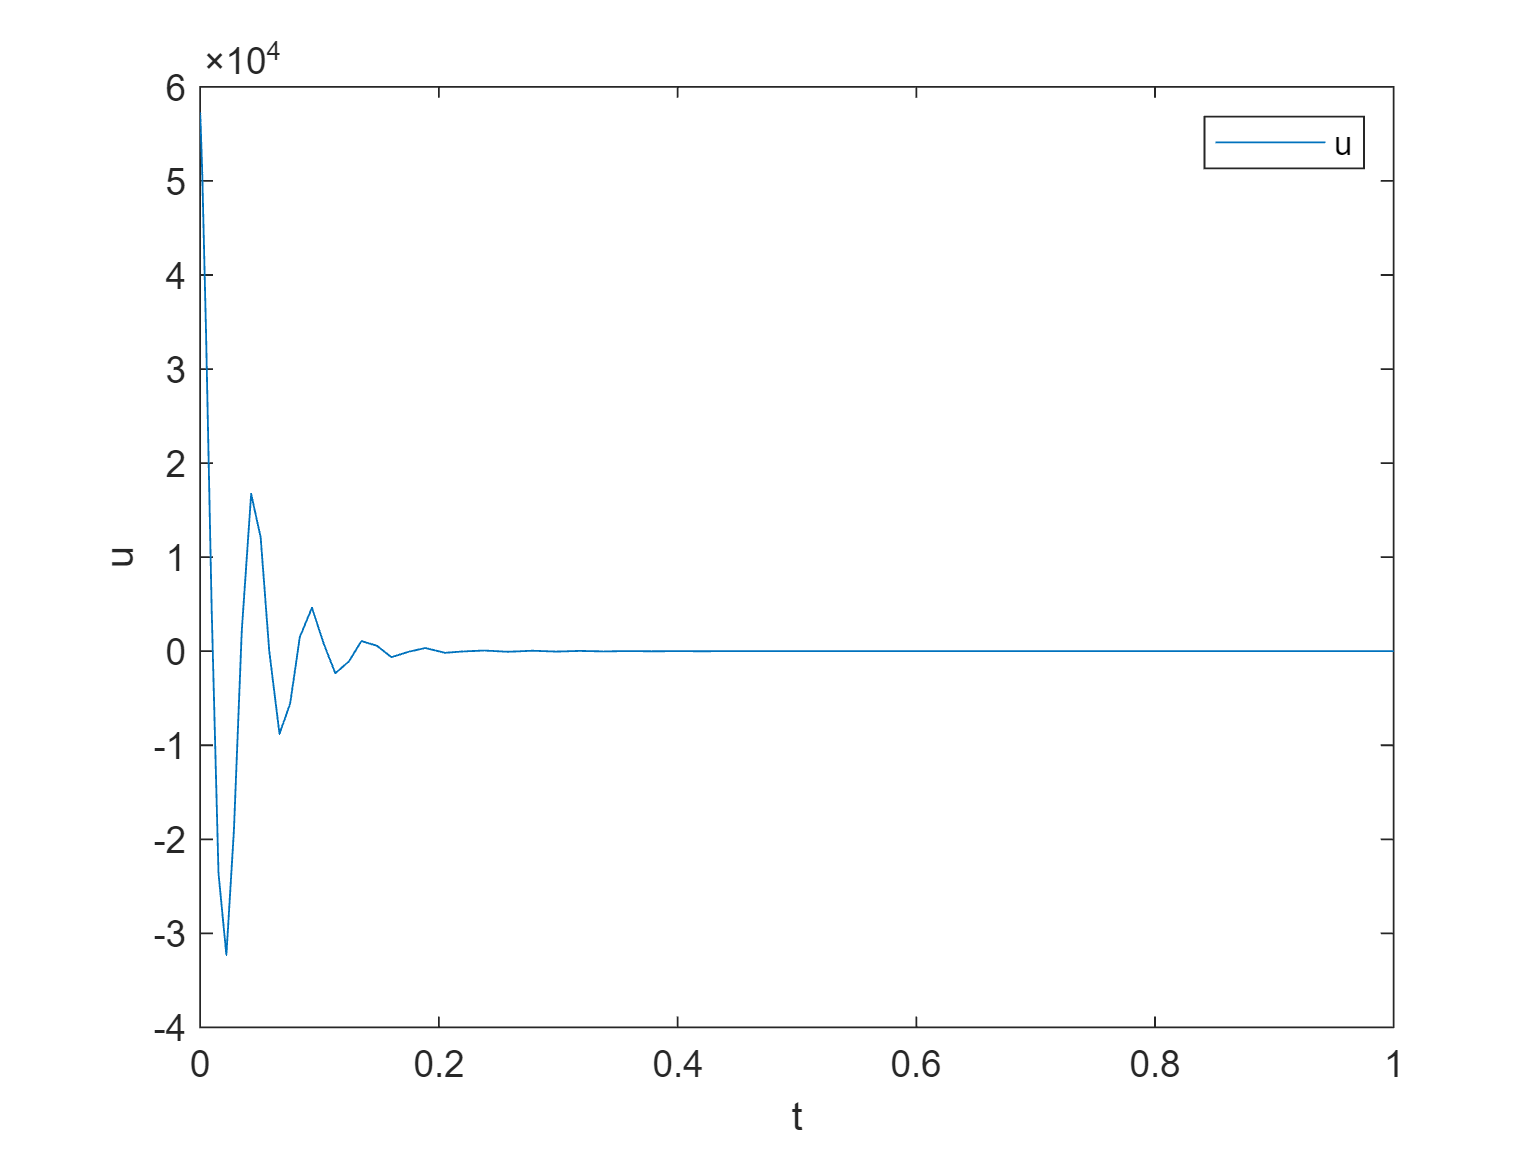

Step Information for the Output:
         RiseTime: 0.0094
    TransientTime: 0.1270
     SettlingTime: 0.1270
      SettlingMin: 2.3450
      SettlingMax: 4.7450
        Overshoot: 51.0373
       Undershoot: 0
             Peak: 4.7450
         PeakTime: 0.0219



close all

K = [18235, 53.9];
kr = 18235;
r=pi;


simOut = sim('closed_loop_v0', 'SimulationMode', 'normal');

% Chiamata alla funzione per visualizzare i risultati
plotSimulationResults(simOut,1);

La risposta del sistema, come ottenuto tramite lo scope, appare parecchio rapida, ma l’eccessiva energia richiesta per un comportamento del genere causa enormi oscillazioni durante il transitorio, infatti:

- il tempo di salita è pari a $0.0094 s$

- la sovraelongazione supera il $50 \%
$ (si ricorda che la sovraelongazione si ottiene come $s_\%=\frac{y_{max}-y_{\infty}}{100}$, e nel caso in esame si ha che $y_{max}=4.7, y_{\infty}=\pi$, quindi la differenza supera il $50 \%
$ del valore a regime)

- il tempo di assestamento è pari a $0.1267s$, ma il quantitativo di oscillazioni a livello di transitorio intacca notevolmente la qualità del controllore

- il valore dell'azione di controllo risultate raggiunge valori elevatissimi, di gran lunga superiori ai limiti, in termini di coppia, di motori che potrebbero essere concretamente utilizzati per il processo in esame

Effettuando un minimo di reverse engineering è possibile indivuare questo sistema tramite il polinomio caratteristico:$s^2+2\zeta \omega_ns+{\omega_n}^2
$ .

Si ottiene che i valori corrispondenti in questo caso per le prestazioni dinamiche del sistema sono: $\omega_n=135, \zeta=0.2$

Come notiamo:

- il coefficiente di smorzamento $\zeta
$ assume un valore troppo basso, di conseguenza la sovraelongazione è esagerata, come descritto in precedenza

- la frequenza naturale $\omega_n$ è molto elevata, garantendo tempi di salita e assestamento molto performanti, ma causando quelle oscillazioni una volta che il sistema raggiunge il regime

## Piano delle fasi per il sistema a ciclo chiuso 

Oltre che analiticamente è possibile avere un'idea anche grafica di ciò che avviene con il controllore proposto dalla traccia, grazie all'ausilio del tool **Phase Plane:**

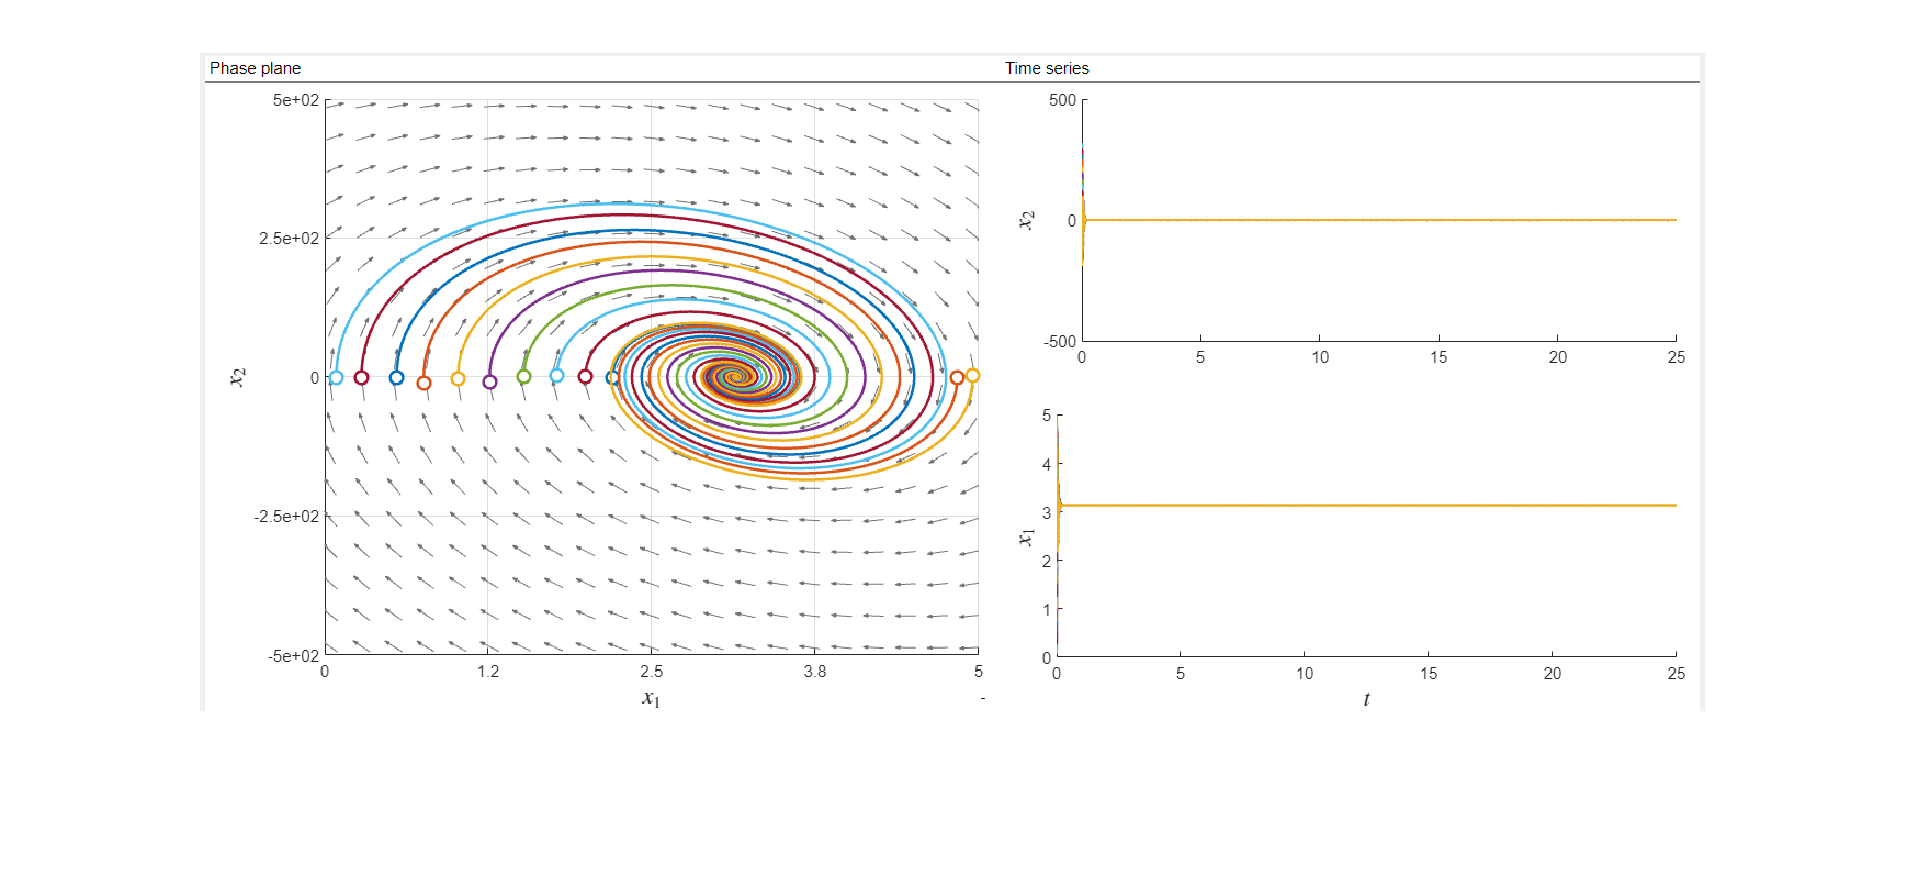

imshow(imread("img/closed_loop_v0_phase.png"))

Come si nota, il controllore stabilizza il sistema intorno al punto $[\pi,0]
$, quindi ha correttamente modificato la dinamica nel modo che era previsto. Le criticità descritte in precedenza sono nuovamente riportate graficamente, si può notare che a partire da condizioni iniziali differenti, il raggiungimento dell'obiettivo avviene con un aumento della velocità, e conseguentemente l'azione di controllo risulta molto elevata.

## Funzione dinamica del sistema

La funzione che utilizziamo per il sistema non lineare, è inserita anche qui per permettere di costruire manualmente il piano delle fasi nella precedente trattazione

function xdot = function_ode_WP1(t, x, u)
    m = 1;
    l = 1;
    g = 9.81;
    b = 0.1;
    x1 = x(1);
    x2 = x(2);
    x1dot = x2;
    x2dot = -((g/l)*sin(x1)) - ((b/(m*(l^2)))*x2) + (u/(m*(l^2)));
    xdot = [x1dot, x2dot].';
end